# OGLO PPC

clear;clc;close all;

cd('D:\Electrophysiology\Matdelane\');
addpath(genpath('matnwb'));
addpath(genpath('matdelane'));
generateCore();

addpath('fieldtrip');ft_defaults;
nwbPath = "data\";

nwbFiles = {dir(nwbPath).name};
nwbFiles = nwbFiles(endsWith(nwbFiles, ".nwb"));

disp("Toolbox setup done.");

Toolbox setup done.


## PART 1: LOAD IN THE DATA

[lfp, dataspike] = create_data(); % to change parameters adjust the function

the input is raw data with 1 channels and 100 trials


## create a spike structure from the continuous structure

spike = ft_checkdata(dataspike,'datatype', 'spike', 'feedback', 'yes');

the input is raw data with 100 channels and 100 trials
converting raw data into spike data


## PART 2: COMPUTE THE SPIKE TRIGGERED SPECTRA

cfg = []; 
cfg.foi = 10:100; 
cfg.taper = 'hann'; 
cfg.t_ftimwin = 5./cfg.foi;     
sts = ft_spiketriggeredspectrum_convol(cfg,lfp,spike);

the input is raw data with 1 channels and 100 trials
the input is spike data with 100 channels


 In ft_checkconfig at line 193
 In ft_spiketriggeredspectrum_convol at line 149

Please wait...
Processing trial 100 from 100

the call to "ft_spiketriggeredspectrum_convol" took 21 seconds and required the additional allocation of an estimated 20 MB


## PART 3: COMPUTE MEASURE OF SPIKE-FIELD ASSOCIATION

## compute the measure of phase locking strength

nNeurons = length(spike.label); 
ppc_all = NaN(nNeurons, length(sts.freq)); 
n_spikes = NaN(nNeurons, length(sts.freq)); 

for iNeuron = 1:nNeurons

    if length(sts.time{iNeuron})<3, continue,end
    
    % the code to compute for a single neuron
    cfg = []; 
    cfg.spikechannel = iNeuron; 
    cfg.method = 'ppc1'; 
    stat_ppc = ft_spiketriggeredspectrum_stat(cfg, sts); % this function takes only one input at a time
    
    % collect the data in some array for all neurons
    ppc_all(iNeuron,:) = stat_ppc.ppc1; % collect the ppc values across units
    n_spikes(iNeuron,:) = stat_ppc.nspikes; % collect the number of spikes for each neuron
end

the input is spike data with 100 channels


Please wait...
Processing trial 21 from 21

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 3 MB
the input is spike data with 100 channels


Please wait...
Processing trial 97 from 97

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 100 from 100

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 1 MB
the input is spike data with 100 channels


Please wait...
Processing trial 90 from 90

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 5 from 5

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 1 MB
the input is spike data with 100 channels


Please wait...
Processing trial 96 from 96

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 91 from 91

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 65 from 65

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 16 from 16

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 100 from 100

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 1 MB
the input is spike data with 100 channels


Please wait...
Processing trial 80 from 80

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 36 from 36

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 1 MB
the input is spike data with 100 channels


Please wait...
Processing trial 100 from 100

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 1 MB
the input is spike data with 100 channels


Please wait...
Processing trial 75 from 75

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 1 MB
the input is spike data with 100 channels


Please wait...
Processing trial 98 from 98

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 1 MB
the input is spike data with 100 channels


Please wait...
Processing trial 99 from 99

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 1 MB
the input is spike data with 100 channels


Please wait...
Processing trial 99 from 99

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 1 MB
the input is spike data with 100 channels


Please wait...
Processing trial 92 from 92

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 1 MB
the input is spike data with 100 channels


Please wait...
Processing trial 87 from 87

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 1 MB
the input is spike data with 100 channels


Please wait...
Processing trial 46 from 46

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 1 MB
the input is spike data with 100 channels


Please wait...
Processing trial 41 from 41

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 1 MB
the input is spike data with 100 channels


Please wait...
Processing trial 74 from 74

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 94 from 94

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 15 from 15

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 65 from 65

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 99 from 99

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 98 from 98

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 88 from 88

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 47 from 47

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 78 from 78

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 54 from 54

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 100 from 100

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 53 from 53

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 75 from 75

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 15 from 15

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 7 from 7

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 42 from 42

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 46 from 46

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 71 from 71

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 73 from 73

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 68 from 68

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 20 from 20

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 97 from 97

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 93 from 93

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 99 from 99

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 64 from 64

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 99 from 99

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 83 from 83

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 91 from 91

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 98 from 98

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 100 from 100

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 97 from 97

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 90 from 90

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 50 from 50

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 68 from 68

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 87 from 87

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 44 from 44

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 100 from 100

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 100 from 100

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 100 from 100

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 79 from 79

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 100 from 100

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 55 from 55

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 58 from 58

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 93 from 93

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 8 MB
the input is spike data with 100 channels


Please wait...
Processing trial 39 from 39

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 1 MB
the input is spike data with 100 channels


Please wait...
Processing trial 100 from 100

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 14 from 14

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 63 from 63

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 93 from 93

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 93 from 93

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 1 MB
the input is spike data with 100 channels


Please wait...
Processing trial 91 from 91

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 95 from 95

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 76 from 76

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 45 from 45

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 60 from 60

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 2 MB
the input is spike data with 100 channels


Please wait...
Processing trial 54 from 54

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 94 from 94

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 89 from 89

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 3 from 3

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 100 from 100

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 79 from 79

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 59 from 59

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 75 from 75

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 94 from 94

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 99 from 99

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 57 from 57

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 72 from 72

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 95 from 95

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 91 from 91

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 63 from 63

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 30 from 30

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 99 from 99

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 41 from 41

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 91 from 91

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 99 from 99

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 97 from 97

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 65 from 65

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 100 from 100

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 40 from 40

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB


## PART 4: VISUALIZE INDIVIDUAL NEURONS AND COMPUTE THE PHASE HISTOGRAM

% Note: this function still expects spike data to come in continuous
% format, as one structure. 
data_all = ft_appenddata([],lfp, dataspike); 

concatenating over the "chan" dimension
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 2 MB
the call to "ft_appenddata" took 0 seconds and required the additional allocation of an estimated 54 MB


sta_all = []; 

for iNeuron = 1:nNeurons

    cfg = []; 
    cfg.spikechannel = dataspike.label{iNeuron};   
    cfg.channel = lfp.label{1};
    sta = ft_spiketriggeredaverage(cfg,data_all);
    sta_all(iNeuron,:) = sta.avg; 

end   

the input is raw data with 101 channels and 100 trials


the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 54 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 2 MB
processing trial 1 of 100 (0 spikes)
processing trial 2 of 100 (0 spikes)
processing trial 3 of 100 (0 spikes)
processing trial 4 of 100 (1 spikes)
processing trial 5 of 100 (0 spikes)
processing trial 6 of 100 (0 spikes)
processing trial 7 of 100 (0 spikes)
processing trial 8 of 100 (0 spikes)
processing trial 9 of 100 (0 spikes)
processing trial 10 of 100 (0 spikes)
processing trial 11 of 100 (0 spikes)
processing trial 12 of 100 (0 spikes)
processing trial 13 of 100 (0 spikes)
processing trial 14 of 100 (0 spikes)
processing trial 15 of 100 (1 spikes)
processing trial 16 of 100 (0 spikes)
processing trial 17 of 100 (0 spikes)
processing trial 18 of 100 (0 spikes)
processing t

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 42 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (3 spikes)
processing trial 2 of 100 (6 spikes)
processing trial 3 of 100 (5 spikes)
processing trial 4 of 100 (4 spikes)
processing trial 5 of 100 (2 spikes)
processing trial 6 of 100 (4 spikes)
processing trial 7 of 100 (2 spikes)
processing trial 8 of 100 (4 spikes)
processing trial 9 of 100 (4 spikes)
processing trial 10 of 100 (1 spikes)
processing trial 11 of 100 (1 spikes)
processing trial 12 of 100 (0 spikes)
processing trial 13 of 100 (3 spikes)
processing trial 14 of 100 (7 spikes)
processing trial 15 of 100 (2 spikes)
processing trial 16 of 100 (3 spikes)
processing trial 17 of 100 (1 spikes)
processing trial 18 of 100 (4 spikes)
processing t

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 14 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (3 spikes)
processing trial 2 of 100 (5 spikes)
processing trial 3 of 100 (3 spikes)
processing trial 4 of 100 (4 spikes)
processing trial 5 of 100 (3 spikes)
processing trial 6 of 100 (12 spikes)
processing trial 7 of 100 (6 spikes)
processing trial 8 of 100 (4 spikes)
processing trial 9 of 100 (4 spikes)
processing trial 10 of 100 (6 spikes)
processing trial 11 of 100 (5 spikes)
processing trial 12 of 100 (6 spikes)
processing trial 13 of 100 (10 spikes)
processing trial 14 of 100 (5 spikes)
processing trial 15 of 100 (2 spikes)
processing trial 16 of 100 (7 spikes)
processing trial 17 of 100 (8 spikes)
processing trial 18 of 100 (3 spikes)
processing

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 24 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (1 spikes)
processing trial 2 of 100 (3 spikes)
processing trial 3 of 100 (3 spikes)
processing trial 4 of 100 (1 spikes)
processing trial 5 of 100 (3 spikes)
processing trial 6 of 100 (2 spikes)
processing trial 7 of 100 (1 spikes)
processing trial 8 of 100 (0 spikes)
processing trial 9 of 100 (1 spikes)
processing trial 10 of 100 (2 spikes)
processing trial 11 of 100 (4 spikes)
processing trial 12 of 100 (2 spikes)
processing trial 13 of 100 (1 spikes)
processing trial 14 of 100 (2 spikes)
processing trial 15 of 100 (2 spikes)
processing trial 16 of 100 (6 spikes)
processing trial 17 of 100 (1 spikes)
processing trial 18 of 100 (1 spikes)
processing t

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 10 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (0 spikes)
processing trial 2 of 100 (0 spikes)
processing trial 3 of 100 (0 spikes)
processing trial 4 of 100 (0 spikes)
processing trial 5 of 100 (0 spikes)
processing trial 6 of 100 (0 spikes)
processing trial 7 of 100 (0 spikes)
processing trial 8 of 100 (0 spikes)
processing trial 9 of 100 (0 spikes)
processing trial 10 of 100 (0 spikes)
processing trial 11 of 100 (0 spikes)
processing trial 12 of 100 (0 spikes)
processing trial 13 of 100 (0 spikes)
processing trial 14 of 100 (0 spikes)
processing trial 15 of 100 (0 spikes)
processing trial 16 of 100 (0 spikes)
processing trial 17 of 100 (0 spikes)
processing trial 18 of 100 (0 spikes)
processing t

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 22 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (3 spikes)
processing trial 2 of 100 (5 spikes)
processing trial 3 of 100 (1 spikes)
processing trial 4 of 100 (4 spikes)
processing trial 5 of 100 (3 spikes)
processing trial 6 of 100 (3 spikes)
processing trial 7 of 100 (3 spikes)
processing trial 8 of 100 (4 spikes)
processing trial 9 of 100 (5 spikes)
processing trial 10 of 100 (3 spikes)
processing trial 11 of 100 (3 spikes)
processing trial 12 of 100 (2 spikes)
processing trial 13 of 100 (2 spikes)
processing trial 14 of 100 (5 spikes)
processing trial 15 of 100 (7 spikes)
processing trial 16 of 100 (1 spikes)
processing trial 17 of 100 (5 spikes)
processing trial 18 of 100 (3 spikes)
processing t

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (1 spikes)
processing trial 2 of 100 (0 spikes)
processing trial 3 of 100 (0 spikes)
processing trial 4 of 100 (5 spikes)
processing trial 5 of 100 (5 spikes)
processing trial 6 of 100 (0 spikes)
processing trial 7 of 100 (3 spikes)
processing trial 8 of 100 (3 spikes)
processing trial 9 of 100 (2 spikes)
processing trial 10 of 100 (4 spikes)
processing trial 11 of 100 (4 spikes)
processing trial 12 of 100 (1 spikes)
processing trial 13 of 100 (3 spikes)
processing trial 14 of 100 (0 spikes)
processing trial 15 of 100 (2 spikes)
processing trial 16 of 100 (3 spikes)
processing trial 17 of 100 (4 spikes)
processing trial 18 of 100 (1 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 35 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (2 spikes)
processing trial 2 of 100 (2 spikes)
processing trial 3 of 100 (1 spikes)
processing trial 4 of 100 (1 spikes)
processing trial 5 of 100 (4 spikes)
processing trial 6 of 100 (2 spikes)
processing trial 7 of 100 (1 spikes)
processing trial 8 of 100 (2 spikes)
processing trial 9 of 100 (3 spikes)
processing trial 10 of 100 (1 spikes)
processing trial 11 of 100 (2 spikes)
processing trial 12 of 100 (2 spikes)
processing trial 13 of 100 (1 spikes)
processing trial 14 of 100 (0 spikes)
processing trial 15 of 100 (0 spikes)
processing trial 16 of 100 (1 spikes)
processing trial 17 of 100 (1 spikes)
processing trial 18 of 100 (1 spikes)
processing t

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 4 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (0 spikes)
processing trial 2 of 100 (0 spikes)
processing trial 3 of 100 (1 spikes)
processing trial 4 of 100 (0 spikes)
processing trial 5 of 100 (1 spikes)
processing trial 6 of 100 (0 spikes)
processing trial 7 of 100 (0 spikes)
processing trial 8 of 100 (1 spikes)
processing trial 9 of 100 (0 spikes)
processing trial 10 of 100 (0 spikes)
processing trial 11 of 100 (0 spikes)
processing trial 12 of 100 (0 spikes)
processing trial 13 of 100 (1 spikes)
processing trial 14 of 100 (0 spikes)
processing trial 15 of 100 (0 spikes)
processing trial 16 of 100 (0 spikes)
processing trial 17 of 100 (0 spikes)
processing trial 18 of 100 (1 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 7 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (9 spikes)
processing trial 2 of 100 (5 spikes)
processing trial 3 of 100 (11 spikes)
processing trial 4 of 100 (11 spikes)
processing trial 5 of 100 (5 spikes)
processing trial 6 of 100 (9 spikes)
processing trial 7 of 100 (13 spikes)
processing trial 8 of 100 (6 spikes)
processing trial 9 of 100 (15 spikes)
processing trial 10 of 100 (6 spikes)
processing trial 11 of 100 (9 spikes)
processing trial 12 of 100 (10 spikes)
processing trial 13 of 100 (9 spikes)
processing trial 14 of 100 (11 spikes)
processing trial 15 of 100 (10 spikes)
processing trial 16 of 100 (3 spikes)
processing trial 17 of 100 (6 spikes)
processing trial 18 of 100 (12 spikes)
proce

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 7 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (2 spikes)
processing trial 2 of 100 (2 spikes)
processing trial 3 of 100 (0 spikes)
processing trial 4 of 100 (2 spikes)
processing trial 5 of 100 (3 spikes)
processing trial 6 of 100 (2 spikes)
processing trial 7 of 100 (3 spikes)
processing trial 8 of 100 (0 spikes)
processing trial 9 of 100 (1 spikes)
processing trial 10 of 100 (1 spikes)
processing trial 11 of 100 (1 spikes)
processing trial 12 of 100 (2 spikes)
processing trial 13 of 100 (1 spikes)
processing trial 14 of 100 (0 spikes)
processing trial 15 of 100 (1 spikes)
processing trial 16 of 100 (2 spikes)
processing trial 17 of 100 (2 spikes)
processing trial 18 of 100 (1 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 2 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (0 spikes)
processing trial 2 of 100 (0 spikes)
processing trial 3 of 100 (0 spikes)
processing trial 4 of 100 (0 spikes)
processing trial 5 of 100 (0 spikes)
processing trial 6 of 100 (1 spikes)
processing trial 7 of 100 (1 spikes)
processing trial 8 of 100 (1 spikes)
processing trial 9 of 100 (0 spikes)
processing trial 10 of 100 (2 spikes)
processing trial 11 of 100 (0 spikes)
processing trial 12 of 100 (0 spikes)
processing trial 13 of 100 (1 spikes)
processing trial 14 of 100 (0 spikes)
processing trial 15 of 100 (1 spikes)
processing trial 16 of 100 (1 spikes)
processing trial 17 of 100 (1 spikes)
processing trial 18 of 100 (0 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 8 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (3 spikes)
processing trial 2 of 100 (4 spikes)
processing trial 3 of 100 (8 spikes)
processing trial 4 of 100 (4 spikes)
processing trial 5 of 100 (3 spikes)
processing trial 6 of 100 (5 spikes)
processing trial 7 of 100 (5 spikes)
processing trial 8 of 100 (3 spikes)
processing trial 9 of 100 (5 spikes)
processing trial 10 of 100 (5 spikes)
processing trial 11 of 100 (4 spikes)
processing trial 12 of 100 (3 spikes)
processing trial 13 of 100 (4 spikes)
processing trial 14 of 100 (5 spikes)
processing trial 15 of 100 (3 spikes)
processing trial 16 of 100 (6 spikes)
processing trial 17 of 100 (5 spikes)
processing trial 18 of 100 (5 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 11 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (1 spikes)
processing trial 2 of 100 (2 spikes)
processing trial 3 of 100 (1 spikes)
processing trial 4 of 100 (1 spikes)
processing trial 5 of 100 (2 spikes)
processing trial 6 of 100 (0 spikes)
processing trial 7 of 100 (1 spikes)
processing trial 8 of 100 (0 spikes)
processing trial 9 of 100 (3 spikes)
processing trial 10 of 100 (2 spikes)
processing trial 11 of 100 (1 spikes)
processing trial 12 of 100 (2 spikes)
processing trial 13 of 100 (0 spikes)
processing trial 14 of 100 (0 spikes)
processing trial 15 of 100 (1 spikes)
processing trial 16 of 100 (0 spikes)
processing trial 17 of 100 (1 spikes)
processing trial 18 of 100 (0 spikes)
processing t

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (3 spikes)
processing trial 2 of 100 (3 spikes)
processing trial 3 of 100 (5 spikes)
processing trial 4 of 100 (4 spikes)
processing trial 5 of 100 (1 spikes)
processing trial 6 of 100 (5 spikes)
processing trial 7 of 100 (2 spikes)
processing trial 8 of 100 (4 spikes)
processing trial 9 of 100 (2 spikes)
processing trial 10 of 100 (2 spikes)
processing trial 11 of 100 (3 spikes)
processing trial 12 of 100 (2 spikes)
processing trial 13 of 100 (3 spikes)
processing trial 14 of 100 (4 spikes)
processing trial 15 of 100 (6 spikes)
processing trial 16 of 100 (12 spikes)
processing trial 17 of 100 (3 spikes)
processing trial 18 of 100 (4 spikes)
processing t

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (5 spikes)
processing trial 2 of 100 (2 spikes)
processing trial 3 of 100 (6 spikes)
processing trial 4 of 100 (4 spikes)
processing trial 5 of 100 (3 spikes)
processing trial 6 of 100 (4 spikes)
processing trial 7 of 100 (3 spikes)
processing trial 8 of 100 (3 spikes)
processing trial 9 of 100 (4 spikes)
processing trial 10 of 100 (5 spikes)
processing trial 11 of 100 (5 spikes)
processing trial 12 of 100 (4 spikes)
processing trial 13 of 100 (5 spikes)
processing trial 14 of 100 (2 spikes)
processing trial 15 of 100 (3 spikes)
processing trial 16 of 100 (4 spikes)
processing trial 17 of 100 (5 spikes)
processing trial 18 of 100 (5 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 3 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (5 spikes)
processing trial 2 of 100 (4 spikes)
processing trial 3 of 100 (3 spikes)
processing trial 4 of 100 (5 spikes)
processing trial 5 of 100 (4 spikes)
processing trial 6 of 100 (5 spikes)
processing trial 7 of 100 (4 spikes)
processing trial 8 of 100 (8 spikes)
processing trial 9 of 100 (5 spikes)
processing trial 10 of 100 (2 spikes)
processing trial 11 of 100 (3 spikes)
processing trial 12 of 100 (7 spikes)
processing trial 13 of 100 (5 spikes)
processing trial 14 of 100 (4 spikes)
processing trial 15 of 100 (5 spikes)
processing trial 16 of 100 (6 spikes)
processing trial 17 of 100 (0 spikes)
processing trial 18 of 100 (7 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 9 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (3 spikes)
processing trial 2 of 100 (3 spikes)
processing trial 3 of 100 (2 spikes)
processing trial 4 of 100 (2 spikes)
processing trial 5 of 100 (2 spikes)
processing trial 6 of 100 (3 spikes)
processing trial 7 of 100 (2 spikes)
processing trial 8 of 100 (2 spikes)
processing trial 9 of 100 (3 spikes)
processing trial 10 of 100 (3 spikes)
processing trial 11 of 100 (3 spikes)
processing trial 12 of 100 (1 spikes)
processing trial 13 of 100 (1 spikes)
processing trial 14 of 100 (1 spikes)
processing trial 15 of 100 (3 spikes)
processing trial 16 of 100 (1 spikes)
processing trial 17 of 100 (2 spikes)
processing trial 18 of 100 (2 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (6 spikes)
processing trial 2 of 100 (5 spikes)
processing trial 3 of 100 (3 spikes)
processing trial 4 of 100 (5 spikes)
processing trial 5 of 100 (2 spikes)
processing trial 6 of 100 (2 spikes)
processing trial 7 of 100 (3 spikes)
processing trial 8 of 100 (0 spikes)
processing trial 9 of 100 (4 spikes)
processing trial 10 of 100 (1 spikes)
processing trial 11 of 100 (3 spikes)
processing trial 12 of 100 (4 spikes)
processing trial 13 of 100 (2 spikes)
processing trial 14 of 100 (2 spikes)
processing trial 15 of 100 (1 spikes)
processing trial 16 of 100 (2 spikes)
processing trial 17 of 100 (2 spikes)
processing trial 18 of 100 (4 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 13 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (1 spikes)
processing trial 2 of 100 (1 spikes)
processing trial 3 of 100 (1 spikes)
processing trial 4 of 100 (1 spikes)
processing trial 5 of 100 (0 spikes)
processing trial 6 of 100 (1 spikes)
processing trial 7 of 100 (0 spikes)
processing trial 8 of 100 (0 spikes)
processing trial 9 of 100 (1 spikes)
processing trial 10 of 100 (1 spikes)
processing trial 11 of 100 (1 spikes)
processing trial 12 of 100 (1 spikes)
processing trial 13 of 100 (1 spikes)
processing trial 14 of 100 (0 spikes)
processing trial 15 of 100 (0 spikes)
processing trial 16 of 100 (2 spikes)
processing trial 17 of 100 (0 spikes)
processing trial 18 of 100 (1 spikes)
processing t

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 4 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 1 MB
processing trial 1 of 100 (0 spikes)
processing trial 2 of 100 (0 spikes)
processing trial 3 of 100 (1 spikes)
processing trial 4 of 100 (2 spikes)
processing trial 5 of 100 (0 spikes)
processing trial 6 of 100 (0 spikes)
processing trial 7 of 100 (0 spikes)
processing trial 8 of 100 (1 spikes)
processing trial 9 of 100 (1 spikes)
processing trial 10 of 100 (0 spikes)
processing trial 11 of 100 (0 spikes)
processing trial 12 of 100 (0 spikes)
processing trial 13 of 100 (1 spikes)
processing trial 14 of 100 (0 spikes)
processing trial 15 of 100 (0 spikes)
processing trial 16 of 100 (1 spikes)
processing trial 17 of 100 (1 spikes)
processing trial 18 of 100 (2 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (2 spikes)
processing trial 2 of 100 (1 spikes)
processing trial 3 of 100 (3 spikes)
processing trial 4 of 100 (0 spikes)
processing trial 5 of 100 (1 spikes)
processing trial 6 of 100 (2 spikes)
processing trial 7 of 100 (5 spikes)
processing trial 8 of 100 (3 spikes)
processing trial 9 of 100 (2 spikes)
processing trial 10 of 100 (1 spikes)
processing trial 11 of 100 (0 spikes)
processing trial 12 of 100 (1 spikes)
processing trial 13 of 100 (2 spikes)
processing trial 14 of 100 (3 spikes)
processing trial 15 of 100 (1 spikes)
processing trial 16 of 100 (2 spikes)
processing trial 17 of 100 (2 spikes)
processing trial 18 of 100 (1 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (1 spikes)
processing trial 2 of 100 (1 spikes)
processing trial 3 of 100 (0 spikes)
processing trial 4 of 100 (3 spikes)
processing trial 5 of 100 (3 spikes)
processing trial 6 of 100 (6 spikes)
processing trial 7 of 100 (3 spikes)
processing trial 8 of 100 (4 spikes)
processing trial 9 of 100 (0 spikes)
processing trial 10 of 100 (4 spikes)
processing trial 11 of 100 (2 spikes)
processing trial 12 of 100 (5 spikes)
processing trial 13 of 100 (5 spikes)
processing trial 14 of 100 (5 spikes)
processing trial 15 of 100 (5 spikes)
processing trial 16 of 100 (5 spikes)
processing trial 17 of 100 (1 spikes)
processing trial 18 of 100 (2 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 1 MB
processing trial 1 of 100 (0 spikes)
processing trial 2 of 100 (0 spikes)
processing trial 3 of 100 (0 spikes)
processing trial 4 of 100 (0 spikes)
processing trial 5 of 100 (0 spikes)
processing trial 6 of 100 (0 spikes)
processing trial 7 of 100 (0 spikes)
processing trial 8 of 100 (0 spikes)
processing trial 9 of 100 (1 spikes)
processing trial 10 of 100 (0 spikes)
processing trial 11 of 100 (0 spikes)
processing trial 12 of 100 (1 spikes)
processing trial 13 of 100 (0 spikes)
processing trial 14 of 100 (0 spikes)
processing trial 15 of 100 (0 spikes)
processing trial 16 of 100 (0 spikes)
processing trial 17 of 100 (0 spikes)
processing trial 18 of 100 (0 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 1 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (1 spikes)
processing trial 2 of 100 (0 spikes)
processing trial 3 of 100 (1 spikes)
processing trial 4 of 100 (1 spikes)
processing trial 5 of 100 (0 spikes)
processing trial 6 of 100 (0 spikes)
processing trial 7 of 100 (0 spikes)
processing trial 8 of 100 (1 spikes)
processing trial 9 of 100 (1 spikes)
processing trial 10 of 100 (0 spikes)
processing trial 11 of 100 (2 spikes)
processing trial 12 of 100 (1 spikes)
processing trial 13 of 100 (2 spikes)
processing trial 14 of 100 (0 spikes)
processing trial 15 of 100 (1 spikes)
processing trial 16 of 100 (1 spikes)
processing trial 17 of 100 (3 spikes)
processing trial 18 of 100 (1 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 5 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (5 spikes)
processing trial 2 of 100 (5 spikes)
processing trial 3 of 100 (4 spikes)
processing trial 4 of 100 (2 spikes)
processing trial 5 of 100 (2 spikes)
processing trial 6 of 100 (3 spikes)
processing trial 7 of 100 (8 spikes)
processing trial 8 of 100 (4 spikes)
processing trial 9 of 100 (6 spikes)
processing trial 10 of 100 (6 spikes)
processing trial 11 of 100 (2 spikes)
processing trial 12 of 100 (3 spikes)
processing trial 13 of 100 (6 spikes)
processing trial 14 of 100 (5 spikes)
processing trial 15 of 100 (5 spikes)
processing trial 16 of 100 (10 spikes)
processing trial 17 of 100 (3 spikes)
processing trial 18 of 100 (5 spikes)
processing t

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 19 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (3 spikes)
processing trial 2 of 100 (5 spikes)
processing trial 3 of 100 (5 spikes)
processing trial 4 of 100 (6 spikes)
processing trial 5 of 100 (8 spikes)
processing trial 6 of 100 (4 spikes)
processing trial 7 of 100 (5 spikes)
processing trial 8 of 100 (4 spikes)
processing trial 9 of 100 (3 spikes)
processing trial 10 of 100 (5 spikes)
processing trial 11 of 100 (2 spikes)
processing trial 12 of 100 (6 spikes)
processing trial 13 of 100 (2 spikes)
processing trial 14 of 100 (5 spikes)
processing trial 15 of 100 (2 spikes)
processing trial 16 of 100 (4 spikes)
processing trial 17 of 100 (4 spikes)
processing trial 18 of 100 (1 spikes)
processing t

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 2 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (2 spikes)
processing trial 2 of 100 (3 spikes)
processing trial 3 of 100 (3 spikes)
processing trial 4 of 100 (2 spikes)
processing trial 5 of 100 (2 spikes)
processing trial 6 of 100 (0 spikes)
processing trial 7 of 100 (2 spikes)
processing trial 8 of 100 (2 spikes)
processing trial 9 of 100 (1 spikes)
processing trial 10 of 100 (0 spikes)
processing trial 11 of 100 (2 spikes)
processing trial 12 of 100 (3 spikes)
processing trial 13 of 100 (3 spikes)
processing trial 14 of 100 (2 spikes)
processing trial 15 of 100 (2 spikes)
processing trial 16 of 100 (0 spikes)
processing trial 17 of 100 (2 spikes)
processing trial 18 of 100 (2 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (0 spikes)
processing trial 2 of 100 (0 spikes)
processing trial 3 of 100 (1 spikes)
processing trial 4 of 100 (0 spikes)
processing trial 5 of 100 (0 spikes)
processing trial 6 of 100 (1 spikes)
processing trial 7 of 100 (2 spikes)
processing trial 8 of 100 (2 spikes)
processing trial 9 of 100 (0 spikes)
processing trial 10 of 100 (0 spikes)
processing trial 11 of 100 (0 spikes)
processing trial 12 of 100 (1 spikes)
processing trial 13 of 100 (0 spikes)
processing trial 14 of 100 (1 spikes)
processing trial 15 of 100 (2 spikes)
processing trial 16 of 100 (0 spikes)
processing trial 17 of 100 (1 spikes)
processing trial 18 of 100 (2 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (0 spikes)
processing trial 2 of 100 (1 spikes)
processing trial 3 of 100 (0 spikes)
processing trial 4 of 100 (0 spikes)
processing trial 5 of 100 (0 spikes)
processing trial 6 of 100 (1 spikes)
processing trial 7 of 100 (0 spikes)
processing trial 8 of 100 (3 spikes)
processing trial 9 of 100 (2 spikes)
processing trial 10 of 100 (3 spikes)
processing trial 11 of 100 (2 spikes)
processing trial 12 of 100 (1 spikes)
processing trial 13 of 100 (4 spikes)
processing trial 14 of 100 (2 spikes)
processing trial 15 of 100 (2 spikes)
processing trial 16 of 100 (5 spikes)
processing trial 17 of 100 (2 spikes)
processing trial 18 of 100 (0 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (0 spikes)
processing trial 2 of 100 (0 spikes)
processing trial 3 of 100 (0 spikes)
processing trial 4 of 100 (1 spikes)
processing trial 5 of 100 (2 spikes)
processing trial 6 of 100 (0 spikes)
processing trial 7 of 100 (0 spikes)
processing trial 8 of 100 (0 spikes)
processing trial 9 of 100 (0 spikes)
processing trial 10 of 100 (3 spikes)
processing trial 11 of 100 (1 spikes)
processing trial 12 of 100 (0 spikes)
processing trial 13 of 100 (0 spikes)
processing trial 14 of 100 (0 spikes)
processing trial 15 of 100 (0 spikes)
processing trial 16 of 100 (1 spikes)
processing trial 17 of 100 (1 spikes)
processing trial 18 of 100 (0 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (6 spikes)
processing trial 2 of 100 (5 spikes)
processing trial 3 of 100 (3 spikes)
processing trial 4 of 100 (10 spikes)
processing trial 5 of 100 (8 spikes)
processing trial 6 of 100 (4 spikes)
processing trial 7 of 100 (4 spikes)
processing trial 8 of 100 (6 spikes)
processing trial 9 of 100 (7 spikes)
processing trial 10 of 100 (6 spikes)
processing trial 11 of 100 (7 spikes)
processing trial 12 of 100 (6 spikes)
processing trial 13 of 100 (6 spikes)
processing trial 14 of 100 (5 spikes)
processing trial 15 of 100 (6 spikes)
processing trial 16 of 100 (5 spikes)
processing trial 17 of 100 (1 spikes)
processing trial 18 of 100 (5 spikes)
processing t

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (3 spikes)
processing trial 2 of 100 (0 spikes)
processing trial 3 of 100 (2 spikes)
processing trial 4 of 100 (0 spikes)
processing trial 5 of 100 (1 spikes)
processing trial 6 of 100 (2 spikes)
processing trial 7 of 100 (1 spikes)
processing trial 8 of 100 (0 spikes)
processing trial 9 of 100 (2 spikes)
processing trial 10 of 100 (0 spikes)
processing trial 11 of 100 (0 spikes)
processing trial 12 of 100 (0 spikes)
processing trial 13 of 100 (4 spikes)
processing trial 14 of 100 (1 spikes)
processing trial 15 of 100 (1 spikes)
processing trial 16 of 100 (0 spikes)
processing trial 17 of 100 (2 spikes)
processing trial 18 of 100 (1 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (1 spikes)
processing trial 2 of 100 (0 spikes)
processing trial 3 of 100 (0 spikes)
processing trial 4 of 100 (3 spikes)
processing trial 5 of 100 (2 spikes)
processing trial 6 of 100 (0 spikes)
processing trial 7 of 100 (0 spikes)
processing trial 8 of 100 (2 spikes)
processing trial 9 of 100 (1 spikes)
processing trial 10 of 100 (3 spikes)
processing trial 11 of 100 (1 spikes)
processing trial 12 of 100 (0 spikes)
processing trial 13 of 100 (4 spikes)
processing trial 14 of 100 (1 spikes)
processing trial 15 of 100 (3 spikes)
processing trial 16 of 100 (0 spikes)
processing trial 17 of 100 (1 spikes)
processing trial 18 of 100 (0 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 3 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (0 spikes)
processing trial 2 of 100 (0 spikes)
processing trial 3 of 100 (0 spikes)
processing trial 4 of 100 (0 spikes)
processing trial 5 of 100 (0 spikes)
processing trial 6 of 100 (0 spikes)
processing trial 7 of 100 (0 spikes)
processing trial 8 of 100 (0 spikes)
processing trial 9 of 100 (0 spikes)
processing trial 10 of 100 (1 spikes)
processing trial 11 of 100 (0 spikes)
processing trial 12 of 100 (0 spikes)
processing trial 13 of 100 (0 spikes)
processing trial 14 of 100 (0 spikes)
processing trial 15 of 100 (0 spikes)
processing trial 16 of 100 (0 spikes)
processing trial 17 of 100 (0 spikes)
processing trial 18 of 100 (0 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 5 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (1 spikes)
processing trial 2 of 100 (0 spikes)
processing trial 3 of 100 (0 spikes)
processing trial 4 of 100 (0 spikes)
processing trial 5 of 100 (0 spikes)
processing trial 6 of 100 (0 spikes)
processing trial 7 of 100 (0 spikes)
processing trial 8 of 100 (0 spikes)
processing trial 9 of 100 (0 spikes)
processing trial 10 of 100 (1 spikes)
processing trial 11 of 100 (0 spikes)
processing trial 12 of 100 (0 spikes)
processing trial 13 of 100 (0 spikes)
processing trial 14 of 100 (0 spikes)
processing trial 15 of 100 (0 spikes)
processing trial 16 of 100 (0 spikes)
processing trial 17 of 100 (0 spikes)
processing trial 18 of 100 (0 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (0 spikes)
processing trial 2 of 100 (0 spikes)
processing trial 3 of 100 (0 spikes)
processing trial 4 of 100 (0 spikes)
processing trial 5 of 100 (0 spikes)
processing trial 6 of 100 (0 spikes)
processing trial 7 of 100 (0 spikes)
processing trial 8 of 100 (1 spikes)
processing trial 9 of 100 (1 spikes)
processing trial 10 of 100 (0 spikes)
processing trial 11 of 100 (0 spikes)
processing trial 12 of 100 (0 spikes)
processing trial 13 of 100 (0 spikes)
processing trial 14 of 100 (3 spikes)
processing trial 15 of 100 (0 spikes)
processing trial 16 of 100 (0 spikes)
processing trial 17 of 100 (4 spikes)
processing trial 18 of 100 (0 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (0 spikes)
processing trial 2 of 100 (0 spikes)
processing trial 3 of 100 (0 spikes)
processing trial 4 of 100 (1 spikes)
processing trial 5 of 100 (0 spikes)
processing trial 6 of 100 (0 spikes)
processing trial 7 of 100 (1 spikes)
processing trial 8 of 100 (0 spikes)
processing trial 9 of 100 (1 spikes)
processing trial 10 of 100 (0 spikes)
processing trial 11 of 100 (1 spikes)
processing trial 12 of 100 (0 spikes)
processing trial 13 of 100 (1 spikes)
processing trial 14 of 100 (0 spikes)
processing trial 15 of 100 (1 spikes)
processing trial 16 of 100 (1 spikes)
processing trial 17 of 100 (0 spikes)
processing trial 18 of 100 (1 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 5 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (3 spikes)
processing trial 2 of 100 (1 spikes)
processing trial 3 of 100 (1 spikes)
processing trial 4 of 100 (0 spikes)
processing trial 5 of 100 (0 spikes)
processing trial 6 of 100 (0 spikes)
processing trial 7 of 100 (1 spikes)
processing trial 8 of 100 (2 spikes)
processing trial 9 of 100 (0 spikes)
processing trial 10 of 100 (1 spikes)
processing trial 11 of 100 (0 spikes)
processing trial 12 of 100 (2 spikes)
processing trial 13 of 100 (2 spikes)
processing trial 14 of 100 (2 spikes)
processing trial 15 of 100 (1 spikes)
processing trial 16 of 100 (1 spikes)
processing trial 17 of 100 (1 spikes)
processing trial 18 of 100 (0 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (1 spikes)
processing trial 2 of 100 (0 spikes)
processing trial 3 of 100 (3 spikes)
processing trial 4 of 100 (3 spikes)
processing trial 5 of 100 (0 spikes)
processing trial 6 of 100 (0 spikes)
processing trial 7 of 100 (3 spikes)
processing trial 8 of 100 (2 spikes)
processing trial 9 of 100 (1 spikes)
processing trial 10 of 100 (2 spikes)
processing trial 11 of 100 (0 spikes)
processing trial 12 of 100 (2 spikes)
processing trial 13 of 100 (1 spikes)
processing trial 14 of 100 (3 spikes)
processing trial 15 of 100 (0 spikes)
processing trial 16 of 100 (1 spikes)
processing trial 17 of 100 (1 spikes)
processing trial 18 of 100 (1 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (3 spikes)
processing trial 2 of 100 (0 spikes)
processing trial 3 of 100 (0 spikes)
processing trial 4 of 100 (2 spikes)
processing trial 5 of 100 (1 spikes)
processing trial 6 of 100 (1 spikes)
processing trial 7 of 100 (2 spikes)
processing trial 8 of 100 (0 spikes)
processing trial 9 of 100 (4 spikes)
processing trial 10 of 100 (2 spikes)
processing trial 11 of 100 (0 spikes)
processing trial 12 of 100 (1 spikes)
processing trial 13 of 100 (0 spikes)
processing trial 14 of 100 (0 spikes)
processing trial 15 of 100 (1 spikes)
processing trial 16 of 100 (1 spikes)
processing trial 17 of 100 (2 spikes)
processing trial 18 of 100 (2 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 3 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (0 spikes)
processing trial 2 of 100 (1 spikes)
processing trial 3 of 100 (1 spikes)
processing trial 4 of 100 (0 spikes)
processing trial 5 of 100 (1 spikes)
processing trial 6 of 100 (0 spikes)
processing trial 7 of 100 (0 spikes)
processing trial 8 of 100 (0 spikes)
processing trial 9 of 100 (0 spikes)
processing trial 10 of 100 (0 spikes)
processing trial 11 of 100 (0 spikes)
processing trial 12 of 100 (0 spikes)
processing trial 13 of 100 (0 spikes)
processing trial 14 of 100 (0 spikes)
processing trial 15 of 100 (1 spikes)
processing trial 16 of 100 (0 spikes)
processing trial 17 of 100 (1 spikes)
processing trial 18 of 100 (0 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (3 spikes)
processing trial 2 of 100 (3 spikes)
processing trial 3 of 100 (4 spikes)
processing trial 4 of 100 (2 spikes)
processing trial 5 of 100 (6 spikes)
processing trial 6 of 100 (3 spikes)
processing trial 7 of 100 (2 spikes)
processing trial 8 of 100 (3 spikes)
processing trial 9 of 100 (2 spikes)
processing trial 10 of 100 (3 spikes)
processing trial 11 of 100 (5 spikes)
processing trial 12 of 100 (4 spikes)
processing trial 13 of 100 (2 spikes)
processing trial 14 of 100 (1 spikes)
processing trial 15 of 100 (1 spikes)
processing trial 16 of 100 (6 spikes)
processing trial 17 of 100 (6 spikes)
processing trial 18 of 100 (4 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (1 spikes)
processing trial 2 of 100 (1 spikes)
processing trial 3 of 100 (0 spikes)
processing trial 4 of 100 (2 spikes)
processing trial 5 of 100 (2 spikes)
processing trial 6 of 100 (2 spikes)
processing trial 7 of 100 (1 spikes)
processing trial 8 of 100 (1 spikes)
processing trial 9 of 100 (1 spikes)
processing trial 10 of 100 (5 spikes)
processing trial 11 of 100 (3 spikes)
processing trial 12 of 100 (3 spikes)
processing trial 13 of 100 (3 spikes)
processing trial 14 of 100 (4 spikes)
processing trial 15 of 100 (3 spikes)
processing trial 16 of 100 (4 spikes)
processing trial 17 of 100 (2 spikes)
processing trial 18 of 100 (3 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 2 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (6 spikes)
processing trial 2 of 100 (7 spikes)
processing trial 3 of 100 (5 spikes)
processing trial 4 of 100 (4 spikes)
processing trial 5 of 100 (4 spikes)
processing trial 6 of 100 (4 spikes)
processing trial 7 of 100 (1 spikes)
processing trial 8 of 100 (6 spikes)
processing trial 9 of 100 (4 spikes)
processing trial 10 of 100 (5 spikes)
processing trial 11 of 100 (5 spikes)
processing trial 12 of 100 (4 spikes)
processing trial 13 of 100 (7 spikes)
processing trial 14 of 100 (1 spikes)
processing trial 15 of 100 (4 spikes)
processing trial 16 of 100 (6 spikes)
processing trial 17 of 100 (5 spikes)
processing trial 18 of 100 (4 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 2 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (2 spikes)
processing trial 2 of 100 (1 spikes)
processing trial 3 of 100 (0 spikes)
processing trial 4 of 100 (2 spikes)
processing trial 5 of 100 (1 spikes)
processing trial 6 of 100 (1 spikes)
processing trial 7 of 100 (2 spikes)
processing trial 8 of 100 (0 spikes)
processing trial 9 of 100 (1 spikes)
processing trial 10 of 100 (3 spikes)
processing trial 11 of 100 (1 spikes)
processing trial 12 of 100 (0 spikes)
processing trial 13 of 100 (0 spikes)
processing trial 14 of 100 (1 spikes)
processing trial 15 of 100 (2 spikes)
processing trial 16 of 100 (1 spikes)
processing trial 17 of 100 (0 spikes)
processing trial 18 of 100 (0 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 3 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (9 spikes)
processing trial 2 of 100 (1 spikes)
processing trial 3 of 100 (4 spikes)
processing trial 4 of 100 (4 spikes)
processing trial 5 of 100 (4 spikes)
processing trial 6 of 100 (6 spikes)
processing trial 7 of 100 (4 spikes)
processing trial 8 of 100 (7 spikes)
processing trial 9 of 100 (2 spikes)
processing trial 10 of 100 (3 spikes)
processing trial 11 of 100 (6 spikes)
processing trial 12 of 100 (5 spikes)
processing trial 13 of 100 (6 spikes)
processing trial 14 of 100 (1 spikes)
processing trial 15 of 100 (4 spikes)
processing trial 16 of 100 (2 spikes)
processing trial 17 of 100 (3 spikes)
processing trial 18 of 100 (6 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (2 spikes)
processing trial 2 of 100 (3 spikes)
processing trial 3 of 100 (2 spikes)
processing trial 4 of 100 (2 spikes)
processing trial 5 of 100 (3 spikes)
processing trial 6 of 100 (1 spikes)
processing trial 7 of 100 (3 spikes)
processing trial 8 of 100 (0 spikes)
processing trial 9 of 100 (1 spikes)
processing trial 10 of 100 (2 spikes)
processing trial 11 of 100 (3 spikes)
processing trial 12 of 100 (3 spikes)
processing trial 13 of 100 (3 spikes)
processing trial 14 of 100 (0 spikes)
processing trial 15 of 100 (1 spikes)
processing trial 16 of 100 (2 spikes)
processing trial 17 of 100 (1 spikes)
processing trial 18 of 100 (2 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 1 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (2 spikes)
processing trial 2 of 100 (3 spikes)
processing trial 3 of 100 (1 spikes)
processing trial 4 of 100 (2 spikes)
processing trial 5 of 100 (7 spikes)
processing trial 6 of 100 (2 spikes)
processing trial 7 of 100 (1 spikes)
processing trial 8 of 100 (2 spikes)
processing trial 9 of 100 (1 spikes)
processing trial 10 of 100 (2 spikes)
processing trial 11 of 100 (2 spikes)
processing trial 12 of 100 (8 spikes)
processing trial 13 of 100 (3 spikes)
processing trial 14 of 100 (2 spikes)
processing trial 15 of 100 (2 spikes)
processing trial 16 of 100 (3 spikes)
processing trial 17 of 100 (3 spikes)
processing trial 18 of 100 (5 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (2 spikes)
processing trial 2 of 100 (3 spikes)
processing trial 3 of 100 (2 spikes)
processing trial 4 of 100 (5 spikes)
processing trial 5 of 100 (4 spikes)
processing trial 6 of 100 (5 spikes)
processing trial 7 of 100 (3 spikes)
processing trial 8 of 100 (4 spikes)
processing trial 9 of 100 (2 spikes)
processing trial 10 of 100 (0 spikes)
processing trial 11 of 100 (4 spikes)
processing trial 12 of 100 (3 spikes)
processing trial 13 of 100 (4 spikes)
processing trial 14 of 100 (5 spikes)
processing trial 15 of 100 (2 spikes)
processing trial 16 of 100 (2 spikes)
processing trial 17 of 100 (4 spikes)
processing trial 18 of 100 (0 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 2 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (15 spikes)
processing trial 2 of 100 (6 spikes)
processing trial 3 of 100 (15 spikes)
processing trial 4 of 100 (13 spikes)
processing trial 5 of 100 (13 spikes)
processing trial 6 of 100 (9 spikes)
processing trial 7 of 100 (8 spikes)
processing trial 8 of 100 (9 spikes)
processing trial 9 of 100 (5 spikes)
processing trial 10 of 100 (7 spikes)
processing trial 11 of 100 (9 spikes)
processing trial 12 of 100 (12 spikes)
processing trial 13 of 100 (6 spikes)
processing trial 14 of 100 (13 spikes)
processing trial 15 of 100 (6 spikes)
processing trial 16 of 100 (10 spikes)
processing trial 17 of 100 (9 spikes)
processing trial 18 of 100 (10 spikes)
proce

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (4 spikes)
processing trial 2 of 100 (6 spikes)
processing trial 3 of 100 (2 spikes)
processing trial 4 of 100 (1 spikes)
processing trial 5 of 100 (8 spikes)
processing trial 6 of 100 (2 spikes)
processing trial 7 of 100 (5 spikes)
processing trial 8 of 100 (6 spikes)
processing trial 9 of 100 (2 spikes)
processing trial 10 of 100 (2 spikes)
processing trial 11 of 100 (0 spikes)
processing trial 12 of 100 (3 spikes)
processing trial 13 of 100 (4 spikes)
processing trial 14 of 100 (3 spikes)
processing trial 15 of 100 (4 spikes)
processing trial 16 of 100 (4 spikes)
processing trial 17 of 100 (2 spikes)
processing trial 18 of 100 (5 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (3 spikes)
processing trial 2 of 100 (2 spikes)
processing trial 3 of 100 (5 spikes)
processing trial 4 of 100 (3 spikes)
processing trial 5 of 100 (3 spikes)
processing trial 6 of 100 (0 spikes)
processing trial 7 of 100 (1 spikes)
processing trial 8 of 100 (1 spikes)
processing trial 9 of 100 (3 spikes)
processing trial 10 of 100 (2 spikes)
processing trial 11 of 100 (2 spikes)
processing trial 12 of 100 (5 spikes)
processing trial 13 of 100 (2 spikes)
processing trial 14 of 100 (1 spikes)
processing trial 15 of 100 (3 spikes)
processing trial 16 of 100 (2 spikes)
processing trial 17 of 100 (2 spikes)
processing trial 18 of 100 (2 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 3 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (0 spikes)
processing trial 2 of 100 (0 spikes)
processing trial 3 of 100 (1 spikes)
processing trial 4 of 100 (1 spikes)
processing trial 5 of 100 (1 spikes)
processing trial 6 of 100 (0 spikes)
processing trial 7 of 100 (0 spikes)
processing trial 8 of 100 (1 spikes)
processing trial 9 of 100 (3 spikes)
processing trial 10 of 100 (1 spikes)
processing trial 11 of 100 (1 spikes)
processing trial 12 of 100 (0 spikes)
processing trial 13 of 100 (3 spikes)
processing trial 14 of 100 (0 spikes)
processing trial 15 of 100 (1 spikes)
processing trial 16 of 100 (0 spikes)
processing trial 17 of 100 (0 spikes)
processing trial 18 of 100 (2 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (2 spikes)
processing trial 2 of 100 (0 spikes)
processing trial 3 of 100 (1 spikes)
processing trial 4 of 100 (1 spikes)
processing trial 5 of 100 (1 spikes)
processing trial 6 of 100 (0 spikes)
processing trial 7 of 100 (0 spikes)
processing trial 8 of 100 (1 spikes)
processing trial 9 of 100 (5 spikes)
processing trial 10 of 100 (1 spikes)
processing trial 11 of 100 (0 spikes)
processing trial 12 of 100 (0 spikes)
processing trial 13 of 100 (1 spikes)
processing trial 14 of 100 (1 spikes)
processing trial 15 of 100 (2 spikes)
processing trial 16 of 100 (0 spikes)
processing trial 17 of 100 (0 spikes)
processing trial 18 of 100 (0 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (2 spikes)
processing trial 2 of 100 (1 spikes)
processing trial 3 of 100 (1 spikes)
processing trial 4 of 100 (0 spikes)
processing trial 5 of 100 (2 spikes)
processing trial 6 of 100 (2 spikes)
processing trial 7 of 100 (1 spikes)
processing trial 8 of 100 (1 spikes)
processing trial 9 of 100 (2 spikes)
processing trial 10 of 100 (3 spikes)
processing trial 11 of 100 (1 spikes)
processing trial 12 of 100 (2 spikes)
processing trial 13 of 100 (1 spikes)
processing trial 14 of 100 (1 spikes)
processing trial 15 of 100 (3 spikes)
processing trial 16 of 100 (7 spikes)
processing trial 17 of 100 (1 spikes)
processing trial 18 of 100 (2 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 1 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (2 spikes)
processing trial 2 of 100 (1 spikes)
processing trial 3 of 100 (0 spikes)
processing trial 4 of 100 (1 spikes)
processing trial 5 of 100 (0 spikes)
processing trial 6 of 100 (0 spikes)
processing trial 7 of 100 (0 spikes)
processing trial 8 of 100 (0 spikes)
processing trial 9 of 100 (1 spikes)
processing trial 10 of 100 (2 spikes)
processing trial 11 of 100 (1 spikes)
processing trial 12 of 100 (1 spikes)
processing trial 13 of 100 (0 spikes)
processing trial 14 of 100 (0 spikes)
processing trial 15 of 100 (1 spikes)
processing trial 16 of 100 (0 spikes)
processing trial 17 of 100 (2 spikes)
processing trial 18 of 100 (0 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 11 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (7 spikes)
processing trial 2 of 100 (6 spikes)
processing trial 3 of 100 (6 spikes)
processing trial 4 of 100 (7 spikes)
processing trial 5 of 100 (8 spikes)
processing trial 6 of 100 (5 spikes)
processing trial 7 of 100 (7 spikes)
processing trial 8 of 100 (6 spikes)
processing trial 9 of 100 (7 spikes)
processing trial 10 of 100 (1 spikes)
processing trial 11 of 100 (8 spikes)
processing trial 12 of 100 (10 spikes)
processing trial 13 of 100 (6 spikes)
processing trial 14 of 100 (6 spikes)
processing trial 15 of 100 (8 spikes)
processing trial 16 of 100 (4 spikes)
processing trial 17 of 100 (9 spikes)
processing trial 18 of 100 (7 spikes)
processing 

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (4 spikes)
processing trial 2 of 100 (5 spikes)
processing trial 3 of 100 (6 spikes)
processing trial 4 of 100 (5 spikes)
processing trial 5 of 100 (2 spikes)
processing trial 6 of 100 (6 spikes)
processing trial 7 of 100 (4 spikes)
processing trial 8 of 100 (4 spikes)
processing trial 9 of 100 (1 spikes)
processing trial 10 of 100 (5 spikes)
processing trial 11 of 100 (6 spikes)
processing trial 12 of 100 (5 spikes)
processing trial 13 of 100 (3 spikes)
processing trial 14 of 100 (5 spikes)
processing trial 15 of 100 (2 spikes)
processing trial 16 of 100 (4 spikes)
processing trial 17 of 100 (12 spikes)
processing trial 18 of 100 (4 spikes)
processing t

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 1 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (9 spikes)
processing trial 2 of 100 (7 spikes)
processing trial 3 of 100 (3 spikes)
processing trial 4 of 100 (6 spikes)
processing trial 5 of 100 (4 spikes)
processing trial 6 of 100 (9 spikes)
processing trial 7 of 100 (6 spikes)
processing trial 8 of 100 (9 spikes)
processing trial 9 of 100 (7 spikes)
processing trial 10 of 100 (8 spikes)
processing trial 11 of 100 (3 spikes)
processing trial 12 of 100 (8 spikes)
processing trial 13 of 100 (6 spikes)
processing trial 14 of 100 (12 spikes)
processing trial 15 of 100 (4 spikes)
processing trial 16 of 100 (4 spikes)
processing trial 17 of 100 (7 spikes)
processing trial 18 of 100 (5 spikes)
processing t

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (0 spikes)
processing trial 2 of 100 (0 spikes)
processing trial 3 of 100 (1 spikes)
processing trial 4 of 100 (2 spikes)
processing trial 5 of 100 (2 spikes)
processing trial 6 of 100 (0 spikes)
processing trial 7 of 100 (0 spikes)
processing trial 8 of 100 (2 spikes)
processing trial 9 of 100 (2 spikes)
processing trial 10 of 100 (2 spikes)
processing trial 11 of 100 (1 spikes)
processing trial 12 of 100 (2 spikes)
processing trial 13 of 100 (1 spikes)
processing trial 14 of 100 (1 spikes)
processing trial 15 of 100 (1 spikes)
processing trial 16 of 100 (0 spikes)
processing trial 17 of 100 (1 spikes)
processing trial 18 of 100 (2 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 2 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (3 spikes)
processing trial 2 of 100 (6 spikes)
processing trial 3 of 100 (4 spikes)
processing trial 4 of 100 (2 spikes)
processing trial 5 of 100 (3 spikes)
processing trial 6 of 100 (3 spikes)
processing trial 7 of 100 (9 spikes)
processing trial 8 of 100 (4 spikes)
processing trial 9 of 100 (5 spikes)
processing trial 10 of 100 (3 spikes)
processing trial 11 of 100 (4 spikes)
processing trial 12 of 100 (1 spikes)
processing trial 13 of 100 (6 spikes)
processing trial 14 of 100 (2 spikes)
processing trial 15 of 100 (5 spikes)
processing trial 16 of 100 (5 spikes)
processing trial 17 of 100 (3 spikes)
processing trial 18 of 100 (3 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 4 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (3 spikes)
processing trial 2 of 100 (1 spikes)
processing trial 3 of 100 (0 spikes)
processing trial 4 of 100 (0 spikes)
processing trial 5 of 100 (0 spikes)
processing trial 6 of 100 (1 spikes)
processing trial 7 of 100 (1 spikes)
processing trial 8 of 100 (2 spikes)
processing trial 9 of 100 (1 spikes)
processing trial 10 of 100 (0 spikes)
processing trial 11 of 100 (1 spikes)
processing trial 12 of 100 (1 spikes)
processing trial 13 of 100 (1 spikes)
processing trial 14 of 100 (0 spikes)
processing trial 15 of 100 (2 spikes)
processing trial 16 of 100 (0 spikes)
processing trial 17 of 100 (1 spikes)
processing trial 18 of 100 (1 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (4 spikes)
processing trial 2 of 100 (2 spikes)
processing trial 3 of 100 (0 spikes)
processing trial 4 of 100 (0 spikes)
processing trial 5 of 100 (0 spikes)
processing trial 6 of 100 (1 spikes)
processing trial 7 of 100 (0 spikes)
processing trial 8 of 100 (0 spikes)
processing trial 9 of 100 (2 spikes)
processing trial 10 of 100 (1 spikes)
processing trial 11 of 100 (1 spikes)
processing trial 12 of 100 (0 spikes)
processing trial 13 of 100 (1 spikes)
processing trial 14 of 100 (1 spikes)
processing trial 15 of 100 (1 spikes)
processing trial 16 of 100 (6 spikes)
processing trial 17 of 100 (0 spikes)
processing trial 18 of 100 (1 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (3 spikes)
processing trial 2 of 100 (3 spikes)
processing trial 3 of 100 (0 spikes)
processing trial 4 of 100 (1 spikes)
processing trial 5 of 100 (5 spikes)
processing trial 6 of 100 (4 spikes)
processing trial 7 of 100 (2 spikes)
processing trial 8 of 100 (4 spikes)
processing trial 9 of 100 (1 spikes)
processing trial 10 of 100 (3 spikes)
processing trial 11 of 100 (0 spikes)
processing trial 12 of 100 (2 spikes)
processing trial 13 of 100 (1 spikes)
processing trial 14 of 100 (4 spikes)
processing trial 15 of 100 (1 spikes)
processing trial 16 of 100 (1 spikes)
processing trial 17 of 100 (1 spikes)
processing trial 18 of 100 (4 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 1 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (0 spikes)
processing trial 2 of 100 (0 spikes)
processing trial 3 of 100 (1 spikes)
processing trial 4 of 100 (1 spikes)
processing trial 5 of 100 (0 spikes)
processing trial 6 of 100 (2 spikes)
processing trial 7 of 100 (0 spikes)
processing trial 8 of 100 (3 spikes)
processing trial 9 of 100 (1 spikes)
processing trial 10 of 100 (0 spikes)
processing trial 11 of 100 (1 spikes)
processing trial 12 of 100 (1 spikes)
processing trial 13 of 100 (0 spikes)
processing trial 14 of 100 (0 spikes)
processing trial 15 of 100 (0 spikes)
processing trial 16 of 100 (0 spikes)
processing trial 17 of 100 (1 spikes)
processing trial 18 of 100 (1 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (6 spikes)
processing trial 2 of 100 (10 spikes)
processing trial 3 of 100 (9 spikes)
processing trial 4 of 100 (12 spikes)
processing trial 5 of 100 (9 spikes)
processing trial 6 of 100 (9 spikes)
processing trial 7 of 100 (9 spikes)
processing trial 8 of 100 (13 spikes)
processing trial 9 of 100 (12 spikes)
processing trial 10 of 100 (14 spikes)
processing trial 11 of 100 (13 spikes)
processing trial 12 of 100 (11 spikes)
processing trial 13 of 100 (9 spikes)
processing trial 14 of 100 (12 spikes)
processing trial 15 of 100 (8 spikes)
processing trial 16 of 100 (11 spikes)
processing trial 17 of 100 (6 spikes)
processing trial 18 of 100 (14 spikes)
pro

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (0 spikes)
processing trial 2 of 100 (0 spikes)
processing trial 3 of 100 (0 spikes)
processing trial 4 of 100 (0 spikes)
processing trial 5 of 100 (0 spikes)
processing trial 6 of 100 (0 spikes)
processing trial 7 of 100 (0 spikes)
processing trial 8 of 100 (1 spikes)
processing trial 9 of 100 (0 spikes)
processing trial 10 of 100 (0 spikes)
processing trial 11 of 100 (0 spikes)
processing trial 12 of 100 (0 spikes)
processing trial 13 of 100 (0 spikes)
processing trial 14 of 100 (0 spikes)
processing trial 15 of 100 (0 spikes)
processing trial 16 of 100 (1 spikes)
processing trial 17 of 100 (1 spikes)
processing trial 18 of 100 (1 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (0 spikes)
processing trial 2 of 100 (2 spikes)
processing trial 3 of 100 (2 spikes)
processing trial 4 of 100 (2 spikes)
processing trial 5 of 100 (2 spikes)
processing trial 6 of 100 (1 spikes)
processing trial 7 of 100 (1 spikes)
processing trial 8 of 100 (1 spikes)
processing trial 9 of 100 (0 spikes)
processing trial 10 of 100 (0 spikes)
processing trial 11 of 100 (1 spikes)
processing trial 12 of 100 (0 spikes)
processing trial 13 of 100 (0 spikes)
processing trial 14 of 100 (1 spikes)
processing trial 15 of 100 (0 spikes)
processing trial 16 of 100 (0 spikes)
processing trial 17 of 100 (2 spikes)
processing trial 18 of 100 (0 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (0 spikes)
processing trial 2 of 100 (1 spikes)
processing trial 3 of 100 (1 spikes)
processing trial 4 of 100 (2 spikes)
processing trial 5 of 100 (2 spikes)
processing trial 6 of 100 (2 spikes)
processing trial 7 of 100 (2 spikes)
processing trial 8 of 100 (3 spikes)
processing trial 9 of 100 (1 spikes)
processing trial 10 of 100 (3 spikes)
processing trial 11 of 100 (2 spikes)
processing trial 12 of 100 (0 spikes)
processing trial 13 of 100 (3 spikes)
processing trial 14 of 100 (3 spikes)
processing trial 15 of 100 (1 spikes)
processing trial 16 of 100 (2 spikes)
processing trial 17 of 100 (2 spikes)
processing trial 18 of 100 (2 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (2 spikes)
processing trial 2 of 100 (1 spikes)
processing trial 3 of 100 (1 spikes)
processing trial 4 of 100 (4 spikes)
processing trial 5 of 100 (3 spikes)
processing trial 6 of 100 (1 spikes)
processing trial 7 of 100 (1 spikes)
processing trial 8 of 100 (3 spikes)
processing trial 9 of 100 (3 spikes)
processing trial 10 of 100 (6 spikes)
processing trial 11 of 100 (2 spikes)
processing trial 12 of 100 (2 spikes)
processing trial 13 of 100 (3 spikes)
processing trial 14 of 100 (2 spikes)
processing trial 15 of 100 (2 spikes)
processing trial 16 of 100 (1 spikes)
processing trial 17 of 100 (1 spikes)
processing trial 18 of 100 (7 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 2 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (3 spikes)
processing trial 2 of 100 (5 spikes)
processing trial 3 of 100 (3 spikes)
processing trial 4 of 100 (3 spikes)
processing trial 5 of 100 (1 spikes)
processing trial 6 of 100 (3 spikes)
processing trial 7 of 100 (2 spikes)
processing trial 8 of 100 (4 spikes)
processing trial 9 of 100 (3 spikes)
processing trial 10 of 100 (3 spikes)
processing trial 11 of 100 (4 spikes)
processing trial 12 of 100 (3 spikes)
processing trial 13 of 100 (3 spikes)
processing trial 14 of 100 (3 spikes)
processing trial 15 of 100 (2 spikes)
processing trial 16 of 100 (0 spikes)
processing trial 17 of 100 (0 spikes)
processing trial 18 of 100 (3 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (6 spikes)
processing trial 2 of 100 (5 spikes)
processing trial 3 of 100 (8 spikes)
processing trial 4 of 100 (3 spikes)
processing trial 5 of 100 (3 spikes)
processing trial 6 of 100 (4 spikes)
processing trial 7 of 100 (6 spikes)
processing trial 8 of 100 (5 spikes)
processing trial 9 of 100 (3 spikes)
processing trial 10 of 100 (2 spikes)
processing trial 11 of 100 (0 spikes)
processing trial 12 of 100 (0 spikes)
processing trial 13 of 100 (3 spikes)
processing trial 14 of 100 (8 spikes)
processing trial 15 of 100 (3 spikes)
processing trial 16 of 100 (4 spikes)
processing trial 17 of 100 (4 spikes)
processing trial 18 of 100 (5 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (1 spikes)
processing trial 2 of 100 (2 spikes)
processing trial 3 of 100 (3 spikes)
processing trial 4 of 100 (0 spikes)
processing trial 5 of 100 (2 spikes)
processing trial 6 of 100 (2 spikes)
processing trial 7 of 100 (1 spikes)
processing trial 8 of 100 (0 spikes)
processing trial 9 of 100 (2 spikes)
processing trial 10 of 100 (3 spikes)
processing trial 11 of 100 (1 spikes)
processing trial 12 of 100 (0 spikes)
processing trial 13 of 100 (2 spikes)
processing trial 14 of 100 (1 spikes)
processing trial 15 of 100 (0 spikes)
processing trial 16 of 100 (0 spikes)
processing trial 17 of 100 (0 spikes)
processing trial 18 of 100 (1 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (1 spikes)
processing trial 2 of 100 (0 spikes)
processing trial 3 of 100 (1 spikes)
processing trial 4 of 100 (2 spikes)
processing trial 5 of 100 (0 spikes)
processing trial 6 of 100 (2 spikes)
processing trial 7 of 100 (0 spikes)
processing trial 8 of 100 (1 spikes)
processing trial 9 of 100 (1 spikes)
processing trial 10 of 100 (0 spikes)
processing trial 11 of 100 (3 spikes)
processing trial 12 of 100 (1 spikes)
processing trial 13 of 100 (0 spikes)
processing trial 14 of 100 (0 spikes)
processing trial 15 of 100 (0 spikes)
processing trial 16 of 100 (0 spikes)
processing trial 17 of 100 (0 spikes)
processing trial 18 of 100 (2 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (1 spikes)
processing trial 2 of 100 (0 spikes)
processing trial 3 of 100 (2 spikes)
processing trial 4 of 100 (1 spikes)
processing trial 5 of 100 (1 spikes)
processing trial 6 of 100 (1 spikes)
processing trial 7 of 100 (1 spikes)
processing trial 8 of 100 (0 spikes)
processing trial 9 of 100 (2 spikes)
processing trial 10 of 100 (2 spikes)
processing trial 11 of 100 (1 spikes)
processing trial 12 of 100 (1 spikes)
processing trial 13 of 100 (1 spikes)
processing trial 14 of 100 (1 spikes)
processing trial 15 of 100 (0 spikes)
processing trial 16 of 100 (1 spikes)
processing trial 17 of 100 (2 spikes)
processing trial 18 of 100 (0 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (0 spikes)
processing trial 2 of 100 (0 spikes)
processing trial 3 of 100 (0 spikes)
processing trial 4 of 100 (2 spikes)
processing trial 5 of 100 (0 spikes)
processing trial 6 of 100 (1 spikes)
processing trial 7 of 100 (1 spikes)
processing trial 8 of 100 (0 spikes)
processing trial 9 of 100 (2 spikes)
processing trial 10 of 100 (0 spikes)
processing trial 11 of 100 (0 spikes)
processing trial 12 of 100 (0 spikes)
processing trial 13 of 100 (3 spikes)
processing trial 14 of 100 (0 spikes)
processing trial 15 of 100 (1 spikes)
processing trial 16 of 100 (0 spikes)
processing trial 17 of 100 (0 spikes)
processing trial 18 of 100 (0 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (2 spikes)
processing trial 2 of 100 (3 spikes)
processing trial 3 of 100 (5 spikes)
processing trial 4 of 100 (5 spikes)
processing trial 5 of 100 (3 spikes)
processing trial 6 of 100 (0 spikes)
processing trial 7 of 100 (3 spikes)
processing trial 8 of 100 (2 spikes)
processing trial 9 of 100 (4 spikes)
processing trial 10 of 100 (8 spikes)
processing trial 11 of 100 (2 spikes)
processing trial 12 of 100 (5 spikes)
processing trial 13 of 100 (7 spikes)
processing trial 14 of 100 (5 spikes)
processing trial 15 of 100 (3 spikes)
processing trial 16 of 100 (3 spikes)
processing trial 17 of 100 (2 spikes)
processing trial 18 of 100 (3 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (1 spikes)
processing trial 2 of 100 (3 spikes)
processing trial 3 of 100 (1 spikes)
processing trial 4 of 100 (1 spikes)
processing trial 5 of 100 (2 spikes)
processing trial 6 of 100 (1 spikes)
processing trial 7 of 100 (2 spikes)
processing trial 8 of 100 (1 spikes)
processing trial 9 of 100 (0 spikes)
processing trial 10 of 100 (3 spikes)
processing trial 11 of 100 (3 spikes)
processing trial 12 of 100 (2 spikes)
processing trial 13 of 100 (2 spikes)
processing trial 14 of 100 (2 spikes)
processing trial 15 of 100 (2 spikes)
processing trial 16 of 100 (1 spikes)
processing trial 17 of 100 (1 spikes)
processing trial 18 of 100 (0 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (0 spikes)
processing trial 2 of 100 (0 spikes)
processing trial 3 of 100 (0 spikes)
processing trial 4 of 100 (0 spikes)
processing trial 5 of 100 (0 spikes)
processing trial 6 of 100 (0 spikes)
processing trial 7 of 100 (0 spikes)
processing trial 8 of 100 (0 spikes)
processing trial 9 of 100 (0 spikes)
processing trial 10 of 100 (0 spikes)
processing trial 11 of 100 (0 spikes)
processing trial 12 of 100 (0 spikes)
processing trial 13 of 100 (0 spikes)
processing trial 14 of 100 (0 spikes)
processing trial 15 of 100 (0 spikes)
processing trial 16 of 100 (0 spikes)
processing trial 17 of 100 (0 spikes)
processing trial 18 of 100 (0 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (8 spikes)
processing trial 2 of 100 (3 spikes)
processing trial 3 of 100 (2 spikes)
processing trial 4 of 100 (11 spikes)
processing trial 5 of 100 (4 spikes)
processing trial 6 of 100 (5 spikes)
processing trial 7 of 100 (6 spikes)
processing trial 8 of 100 (7 spikes)
processing trial 9 of 100 (11 spikes)
processing trial 10 of 100 (3 spikes)
processing trial 11 of 100 (1 spikes)
processing trial 12 of 100 (5 spikes)
processing trial 13 of 100 (3 spikes)
processing trial 14 of 100 (5 spikes)
processing trial 15 of 100 (3 spikes)
processing trial 16 of 100 (9 spikes)
processing trial 17 of 100 (9 spikes)
processing trial 18 of 100 (4 spikes)
processing 

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (2 spikes)
processing trial 2 of 100 (2 spikes)
processing trial 3 of 100 (0 spikes)
processing trial 4 of 100 (0 spikes)
processing trial 5 of 100 (1 spikes)
processing trial 6 of 100 (0 spikes)
processing trial 7 of 100 (2 spikes)
processing trial 8 of 100 (1 spikes)
processing trial 9 of 100 (4 spikes)
processing trial 10 of 100 (1 spikes)
processing trial 11 of 100 (1 spikes)
processing trial 12 of 100 (1 spikes)
processing trial 13 of 100 (0 spikes)
processing trial 14 of 100 (6 spikes)
processing trial 15 of 100 (2 spikes)
processing trial 16 of 100 (0 spikes)
processing trial 17 of 100 (2 spikes)
processing trial 18 of 100 (0 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (0 spikes)
processing trial 2 of 100 (1 spikes)
processing trial 3 of 100 (0 spikes)
processing trial 4 of 100 (2 spikes)
processing trial 5 of 100 (1 spikes)
processing trial 6 of 100 (1 spikes)
processing trial 7 of 100 (0 spikes)
processing trial 8 of 100 (0 spikes)
processing trial 9 of 100 (0 spikes)
processing trial 10 of 100 (1 spikes)
processing trial 11 of 100 (0 spikes)
processing trial 12 of 100 (2 spikes)
processing trial 13 of 100 (1 spikes)
processing trial 14 of 100 (1 spikes)
processing trial 15 of 100 (0 spikes)
processing trial 16 of 100 (1 spikes)
processing trial 17 of 100 (0 spikes)
processing trial 18 of 100 (0 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 8 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (0 spikes)
processing trial 2 of 100 (0 spikes)
processing trial 3 of 100 (2 spikes)
processing trial 4 of 100 (1 spikes)
processing trial 5 of 100 (3 spikes)
processing trial 6 of 100 (1 spikes)
processing trial 7 of 100 (1 spikes)
processing trial 8 of 100 (1 spikes)
processing trial 9 of 100 (2 spikes)
processing trial 10 of 100 (0 spikes)
processing trial 11 of 100 (1 spikes)
processing trial 12 of 100 (1 spikes)
processing trial 13 of 100 (0 spikes)
processing trial 14 of 100 (0 spikes)
processing trial 15 of 100 (1 spikes)
processing trial 16 of 100 (4 spikes)
processing trial 17 of 100 (1 spikes)
processing trial 18 of 100 (3 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (4 spikes)
processing trial 2 of 100 (1 spikes)
processing trial 3 of 100 (4 spikes)
processing trial 4 of 100 (0 spikes)
processing trial 5 of 100 (3 spikes)
processing trial 6 of 100 (2 spikes)
processing trial 7 of 100 (3 spikes)
processing trial 8 of 100 (4 spikes)
processing trial 9 of 100 (1 spikes)
processing trial 10 of 100 (4 spikes)
processing trial 11 of 100 (2 spikes)
processing trial 12 of 100 (3 spikes)
processing trial 13 of 100 (3 spikes)
processing trial 14 of 100 (2 spikes)
processing trial 15 of 100 (3 spikes)
processing trial 16 of 100 (0 spikes)
processing trial 17 of 100 (3 spikes)
processing trial 18 of 100 (4 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (6 spikes)
processing trial 2 of 100 (2 spikes)
processing trial 3 of 100 (5 spikes)
processing trial 4 of 100 (3 spikes)
processing trial 5 of 100 (4 spikes)
processing trial 6 of 100 (6 spikes)
processing trial 7 of 100 (1 spikes)
processing trial 8 of 100 (5 spikes)
processing trial 9 of 100 (4 spikes)
processing trial 10 of 100 (5 spikes)
processing trial 11 of 100 (7 spikes)
processing trial 12 of 100 (2 spikes)
processing trial 13 of 100 (3 spikes)
processing trial 14 of 100 (4 spikes)
processing trial 15 of 100 (6 spikes)
processing trial 16 of 100 (6 spikes)
processing trial 17 of 100 (5 spikes)
processing trial 18 of 100 (4 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 3 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (4 spikes)
processing trial 2 of 100 (1 spikes)
processing trial 3 of 100 (0 spikes)
processing trial 4 of 100 (2 spikes)
processing trial 5 of 100 (1 spikes)
processing trial 6 of 100 (1 spikes)
processing trial 7 of 100 (1 spikes)
processing trial 8 of 100 (0 spikes)
processing trial 9 of 100 (1 spikes)
processing trial 10 of 100 (0 spikes)
processing trial 11 of 100 (1 spikes)
processing trial 12 of 100 (0 spikes)
processing trial 13 of 100 (0 spikes)
processing trial 14 of 100 (2 spikes)
processing trial 15 of 100 (0 spikes)
processing trial 16 of 100 (1 spikes)
processing trial 17 of 100 (1 spikes)
processing trial 18 of 100 (1 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (1 spikes)
processing trial 2 of 100 (1 spikes)
processing trial 3 of 100 (3 spikes)
processing trial 4 of 100 (0 spikes)
processing trial 5 of 100 (0 spikes)
processing trial 6 of 100 (0 spikes)
processing trial 7 of 100 (3 spikes)
processing trial 8 of 100 (1 spikes)
processing trial 9 of 100 (1 spikes)
processing trial 10 of 100 (2 spikes)
processing trial 11 of 100 (2 spikes)
processing trial 12 of 100 (2 spikes)
processing trial 13 of 100 (2 spikes)
processing trial 14 of 100 (0 spikes)
processing trial 15 of 100 (4 spikes)
processing trial 16 of 100 (0 spikes)
processing trial 17 of 100 (2 spikes)
processing trial 18 of 100 (4 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (6 spikes)
processing trial 2 of 100 (2 spikes)
processing trial 3 of 100 (1 spikes)
processing trial 4 of 100 (3 spikes)
processing trial 5 of 100 (1 spikes)
processing trial 6 of 100 (2 spikes)
processing trial 7 of 100 (3 spikes)
processing trial 8 of 100 (3 spikes)
processing trial 9 of 100 (1 spikes)
processing trial 10 of 100 (3 spikes)
processing trial 11 of 100 (1 spikes)
processing trial 12 of 100 (4 spikes)
processing trial 13 of 100 (5 spikes)
processing trial 14 of 100 (7 spikes)
processing trial 15 of 100 (1 spikes)
processing trial 16 of 100 (4 spikes)
processing trial 17 of 100 (0 spikes)
processing trial 18 of 100 (2 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (1 spikes)
processing trial 2 of 100 (2 spikes)
processing trial 3 of 100 (1 spikes)
processing trial 4 of 100 (3 spikes)
processing trial 5 of 100 (1 spikes)
processing trial 6 of 100 (0 spikes)
processing trial 7 of 100 (2 spikes)
processing trial 8 of 100 (2 spikes)
processing trial 9 of 100 (3 spikes)
processing trial 10 of 100 (2 spikes)
processing trial 11 of 100 (4 spikes)
processing trial 12 of 100 (1 spikes)
processing trial 13 of 100 (1 spikes)
processing trial 14 of 100 (4 spikes)
processing trial 15 of 100 (6 spikes)
processing trial 16 of 100 (1 spikes)
processing trial 17 of 100 (2 spikes)
processing trial 18 of 100 (1 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 1 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (2 spikes)
processing trial 2 of 100 (2 spikes)
processing trial 3 of 100 (0 spikes)
processing trial 4 of 100 (2 spikes)
processing trial 5 of 100 (3 spikes)
processing trial 6 of 100 (1 spikes)
processing trial 7 of 100 (1 spikes)
processing trial 8 of 100 (1 spikes)
processing trial 9 of 100 (2 spikes)
processing trial 10 of 100 (2 spikes)
processing trial 11 of 100 (2 spikes)
processing trial 12 of 100 (3 spikes)
processing trial 13 of 100 (1 spikes)
processing trial 14 of 100 (1 spikes)
processing trial 15 of 100 (1 spikes)
processing trial 16 of 100 (0 spikes)
processing trial 17 of 100 (1 spikes)
processing trial 18 of 100 (0 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (0 spikes)
processing trial 2 of 100 (0 spikes)
processing trial 3 of 100 (0 spikes)
processing trial 4 of 100 (0 spikes)
processing trial 5 of 100 (1 spikes)
processing trial 6 of 100 (1 spikes)
processing trial 7 of 100 (0 spikes)
processing trial 8 of 100 (0 spikes)
processing trial 9 of 100 (1 spikes)
processing trial 10 of 100 (0 spikes)
processing trial 11 of 100 (0 spikes)
processing trial 12 of 100 (0 spikes)
processing trial 13 of 100 (0 spikes)
processing trial 14 of 100 (0 spikes)
processing trial 15 of 100 (0 spikes)
processing trial 16 of 100 (0 spikes)
processing trial 17 of 100 (1 spikes)
processing trial 18 of 100 (0 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (0 spikes)
processing trial 2 of 100 (4 spikes)
processing trial 3 of 100 (5 spikes)
processing trial 4 of 100 (3 spikes)
processing trial 5 of 100 (2 spikes)
processing trial 6 of 100 (4 spikes)
processing trial 7 of 100 (5 spikes)
processing trial 8 of 100 (7 spikes)
processing trial 9 of 100 (6 spikes)
processing trial 10 of 100 (8 spikes)
processing trial 11 of 100 (3 spikes)
processing trial 12 of 100 (2 spikes)
processing trial 13 of 100 (6 spikes)
processing trial 14 of 100 (1 spikes)
processing trial 15 of 100 (6 spikes)
processing trial 16 of 100 (3 spikes)
processing trial 17 of 100 (2 spikes)
processing trial 18 of 100 (3 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 14 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (3 spikes)
processing trial 2 of 100 (1 spikes)
processing trial 3 of 100 (1 spikes)
processing trial 4 of 100 (1 spikes)
processing trial 5 of 100 (1 spikes)
processing trial 6 of 100 (0 spikes)
processing trial 7 of 100 (1 spikes)
processing trial 8 of 100 (1 spikes)
processing trial 9 of 100 (0 spikes)
processing trial 10 of 100 (0 spikes)
processing trial 11 of 100 (0 spikes)
processing trial 12 of 100 (0 spikes)
processing trial 13 of 100 (0 spikes)
processing trial 14 of 100 (0 spikes)
processing trial 15 of 100 (1 spikes)
processing trial 16 of 100 (1 spikes)
processing trial 17 of 100 (1 spikes)
processing trial 18 of 100 (0 spikes)
processing t

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (3 spikes)
processing trial 2 of 100 (2 spikes)
processing trial 3 of 100 (2 spikes)
processing trial 4 of 100 (5 spikes)
processing trial 5 of 100 (5 spikes)
processing trial 6 of 100 (2 spikes)
processing trial 7 of 100 (2 spikes)
processing trial 8 of 100 (6 spikes)
processing trial 9 of 100 (0 spikes)
processing trial 10 of 100 (3 spikes)
processing trial 11 of 100 (2 spikes)
processing trial 12 of 100 (3 spikes)
processing trial 13 of 100 (1 spikes)
processing trial 14 of 100 (1 spikes)
processing trial 15 of 100 (1 spikes)
processing trial 16 of 100 (5 spikes)
processing trial 17 of 100 (3 spikes)
processing trial 18 of 100 (2 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (7 spikes)
processing trial 2 of 100 (6 spikes)
processing trial 3 of 100 (4 spikes)
processing trial 4 of 100 (2 spikes)
processing trial 5 of 100 (3 spikes)
processing trial 6 of 100 (4 spikes)
processing trial 7 of 100 (2 spikes)
processing trial 8 of 100 (6 spikes)
processing trial 9 of 100 (3 spikes)
processing trial 10 of 100 (3 spikes)
processing trial 11 of 100 (3 spikes)
processing trial 12 of 100 (5 spikes)
processing trial 13 of 100 (4 spikes)
processing trial 14 of 100 (2 spikes)
processing trial 15 of 100 (5 spikes)
processing trial 16 of 100 (2 spikes)
processing trial 17 of 100 (1 spikes)
processing trial 18 of 100 (3 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (2 spikes)
processing trial 2 of 100 (4 spikes)
processing trial 3 of 100 (1 spikes)
processing trial 4 of 100 (6 spikes)
processing trial 5 of 100 (4 spikes)
processing trial 6 of 100 (5 spikes)
processing trial 7 of 100 (1 spikes)
processing trial 8 of 100 (4 spikes)
processing trial 9 of 100 (3 spikes)
processing trial 10 of 100 (1 spikes)
processing trial 11 of 100 (1 spikes)
processing trial 12 of 100 (5 spikes)
processing trial 13 of 100 (3 spikes)
processing trial 14 of 100 (6 spikes)
processing trial 15 of 100 (3 spikes)
processing trial 16 of 100 (2 spikes)
processing trial 17 of 100 (7 spikes)
processing trial 18 of 100 (3 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (2 spikes)
processing trial 2 of 100 (2 spikes)
processing trial 3 of 100 (0 spikes)
processing trial 4 of 100 (0 spikes)
processing trial 5 of 100 (4 spikes)
processing trial 6 of 100 (0 spikes)
processing trial 7 of 100 (4 spikes)
processing trial 8 of 100 (0 spikes)
processing trial 9 of 100 (4 spikes)
processing trial 10 of 100 (0 spikes)
processing trial 11 of 100 (0 spikes)
processing trial 12 of 100 (0 spikes)
processing trial 13 of 100 (3 spikes)
processing trial 14 of 100 (1 spikes)
processing trial 15 of 100 (0 spikes)
processing trial 16 of 100 (1 spikes)
processing trial 17 of 100 (1 spikes)
processing trial 18 of 100 (0 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (5 spikes)
processing trial 2 of 100 (4 spikes)
processing trial 3 of 100 (6 spikes)
processing trial 4 of 100 (9 spikes)
processing trial 5 of 100 (2 spikes)
processing trial 6 of 100 (5 spikes)
processing trial 7 of 100 (9 spikes)
processing trial 8 of 100 (5 spikes)
processing trial 9 of 100 (2 spikes)
processing trial 10 of 100 (7 spikes)
processing trial 11 of 100 (3 spikes)
processing trial 12 of 100 (9 spikes)
processing trial 13 of 100 (8 spikes)
processing trial 14 of 100 (8 spikes)
processing trial 15 of 100 (4 spikes)
processing trial 16 of 100 (1 spikes)
processing trial 17 of 100 (5 spikes)
processing trial 18 of 100 (9 spikes)
processing tr

the input is raw data with 101 channels and 100 trials
removing 0 trials in which no data was selected
the call to "ft_redefinetrial" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
processing trial 1 of 100 (2 spikes)
processing trial 2 of 100 (0 spikes)
processing trial 3 of 100 (1 spikes)
processing trial 4 of 100 (1 spikes)
processing trial 5 of 100 (0 spikes)
processing trial 6 of 100 (0 spikes)
processing trial 7 of 100 (0 spikes)
processing trial 8 of 100 (0 spikes)
processing trial 9 of 100 (0 spikes)
processing trial 10 of 100 (0 spikes)
processing trial 11 of 100 (0 spikes)
processing trial 12 of 100 (0 spikes)
processing trial 13 of 100 (1 spikes)
processing trial 14 of 100 (0 spikes)
processing trial 15 of 100 (1 spikes)
processing trial 16 of 100 (0 spikes)
processing trial 17 of 100 (0 spikes)
processing trial 18 of 100 (1 spikes)
processing tr

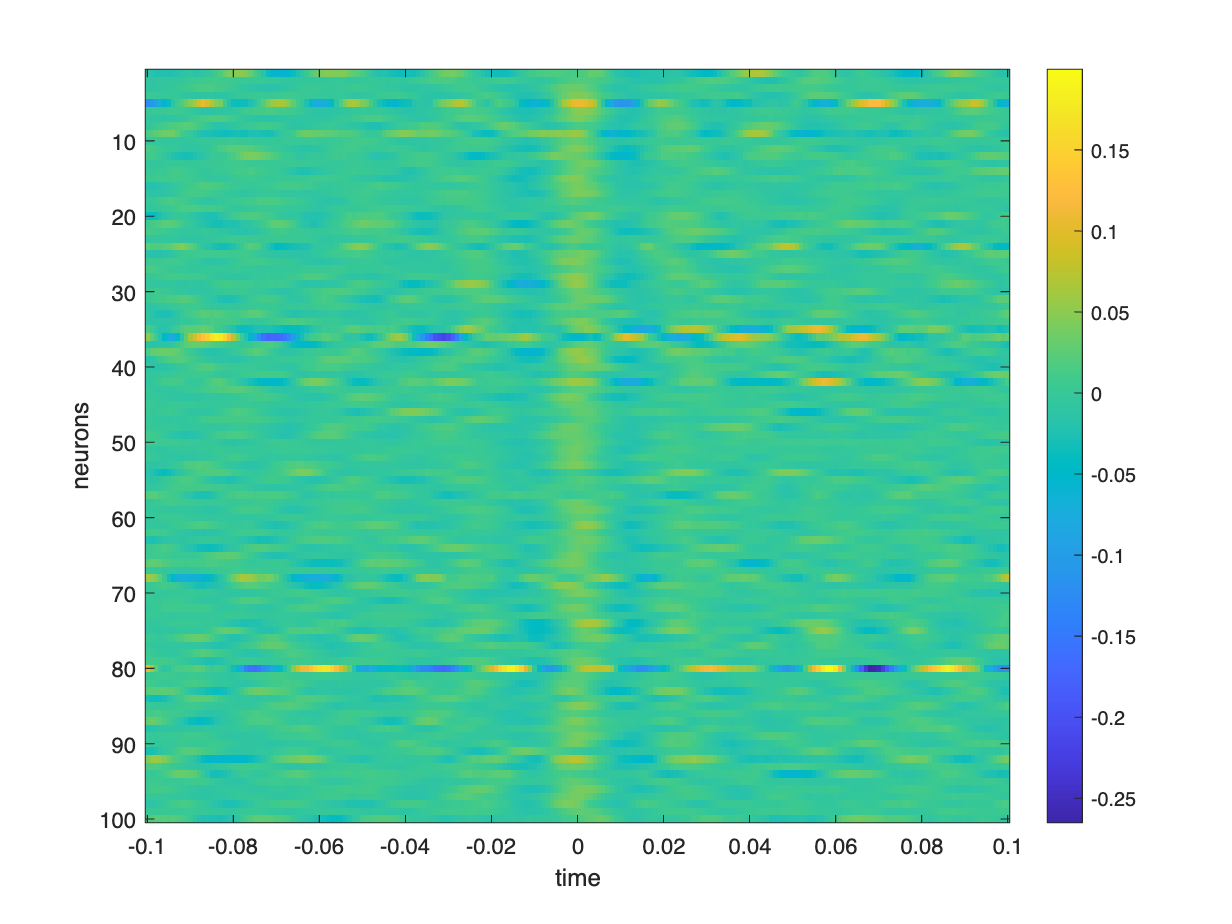


figure, imagesc(sta.time, 1:nNeurons, sta_all), colorbar
xlabel('time')
ylabel('neurons')

the input is spike data with 100 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB


the input is spike data with 100 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB


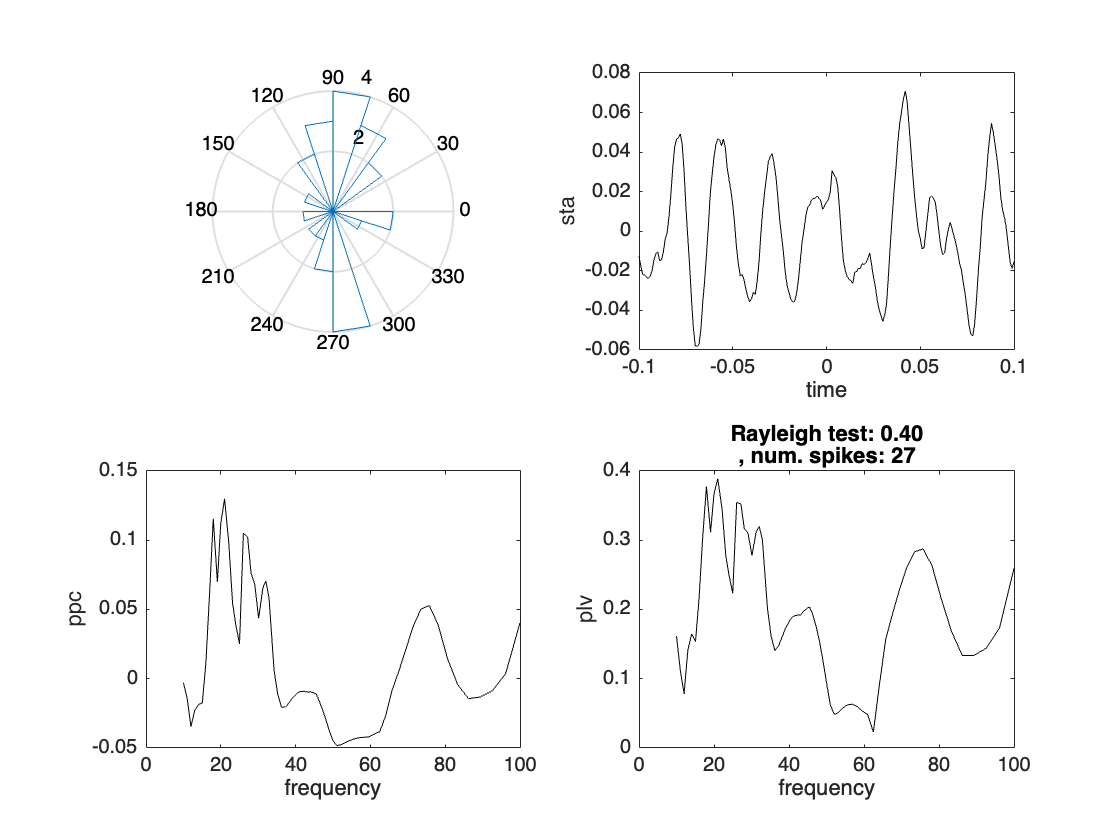

the input is spike data with 100 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB


the input is spike data with 100 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB


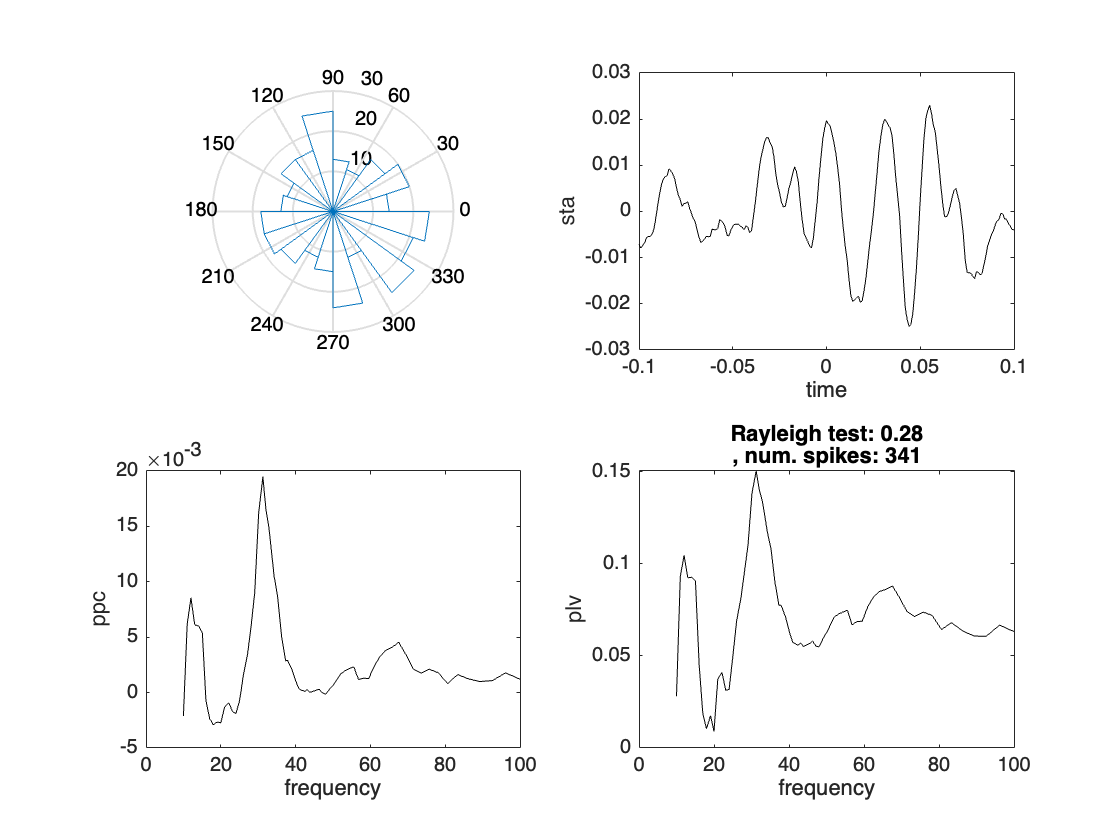

the input is spike data with 100 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB


the input is spike data with 100 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB


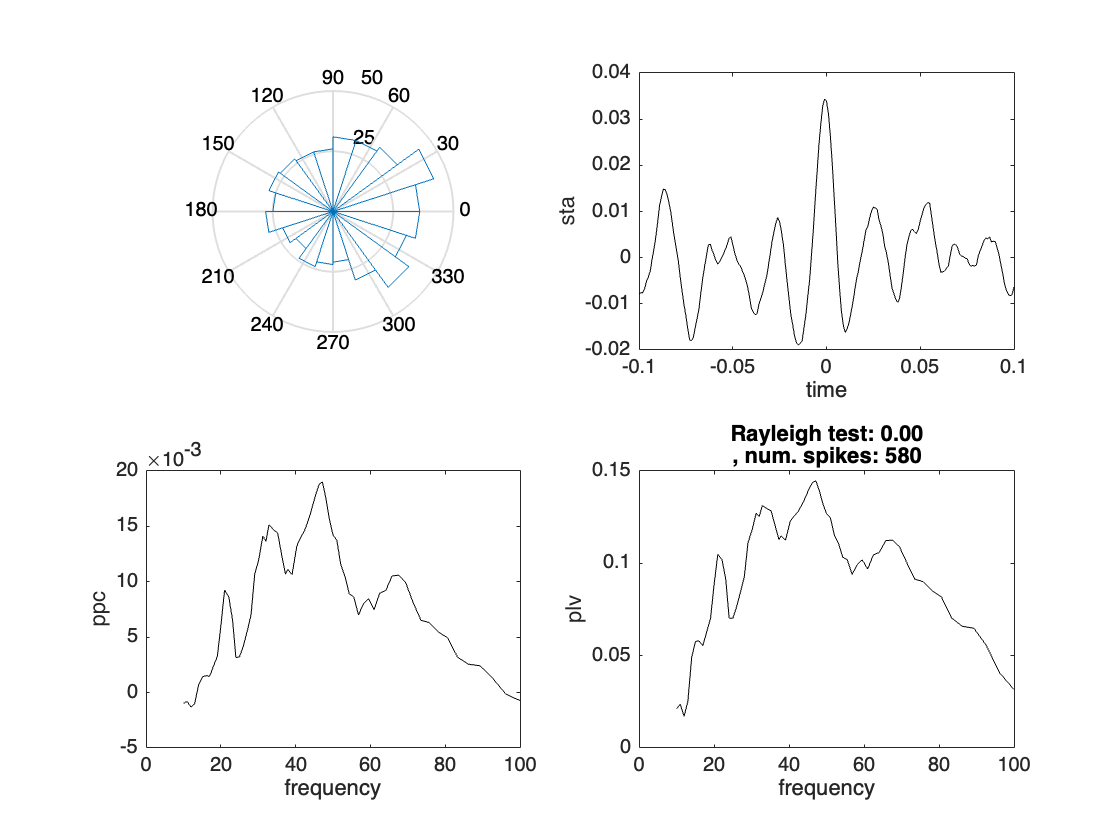

the input is spike data with 100 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB


the input is spike data with 100 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB


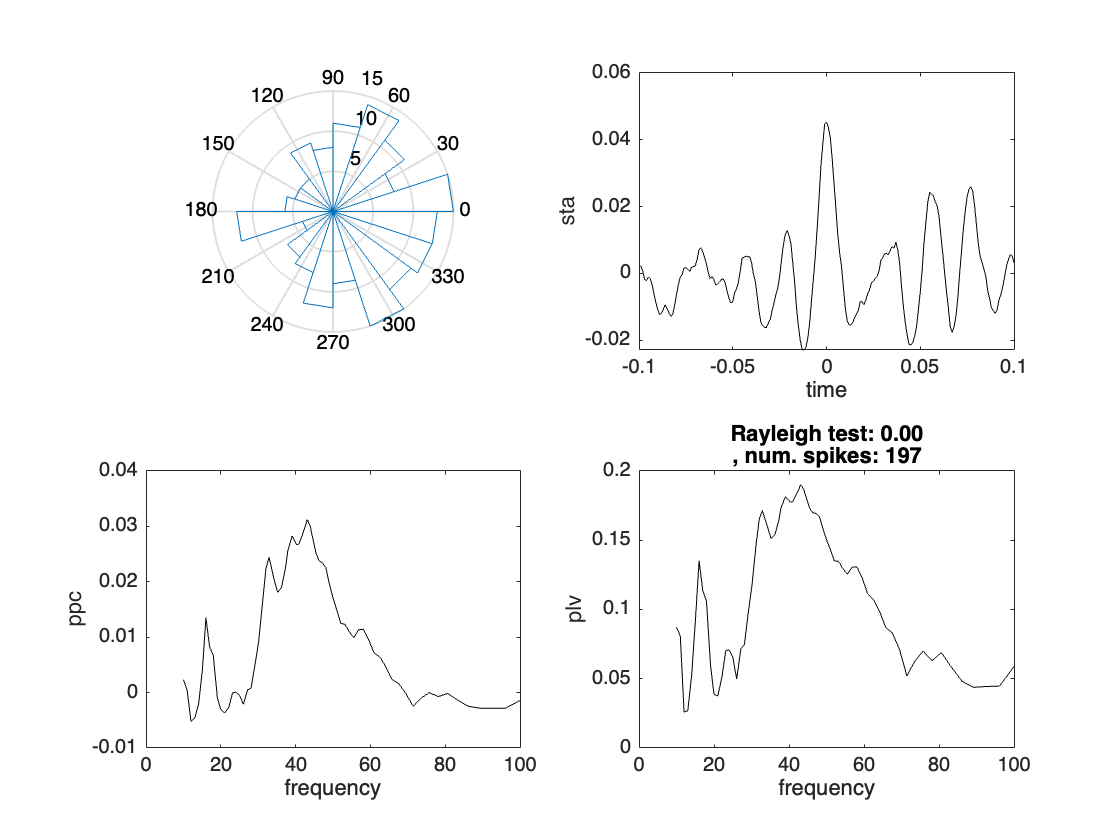

the input is spike data with 100 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB


the input is spike data with 100 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB


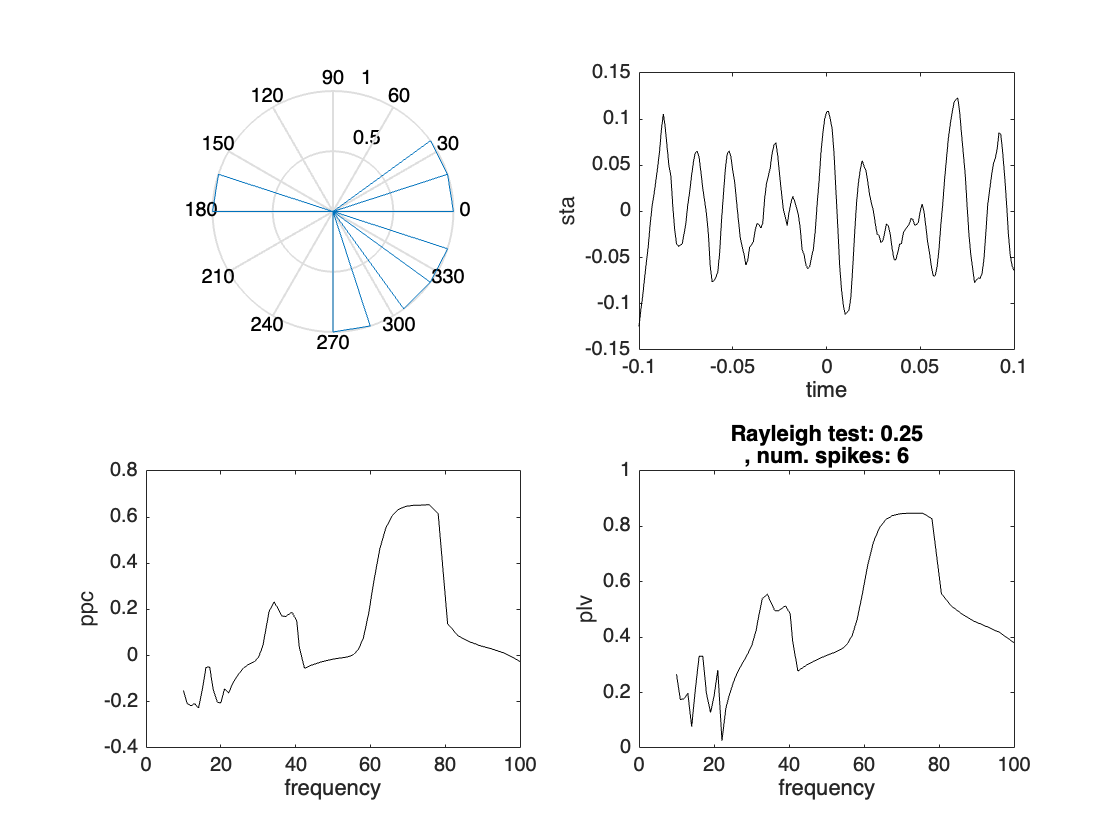

the input is spike data with 100 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB


the input is spike data with 100 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB


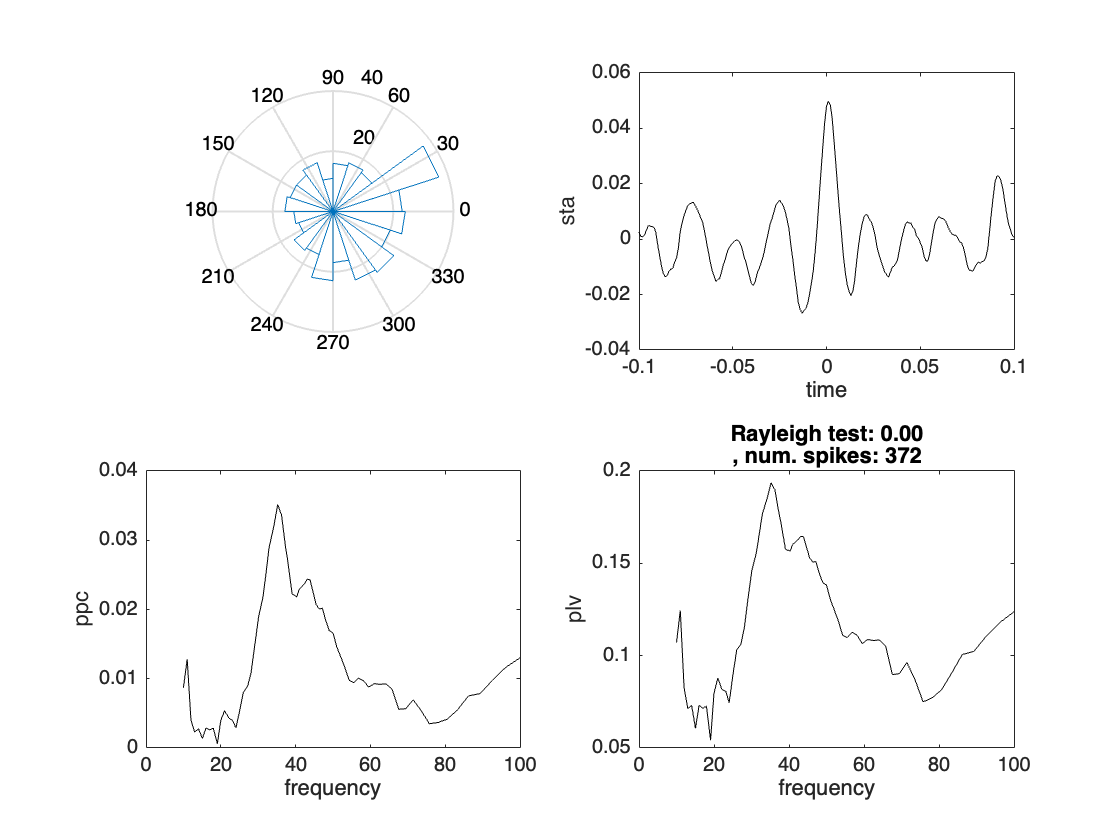

the input is spike data with 100 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB


the input is spike data with 100 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB


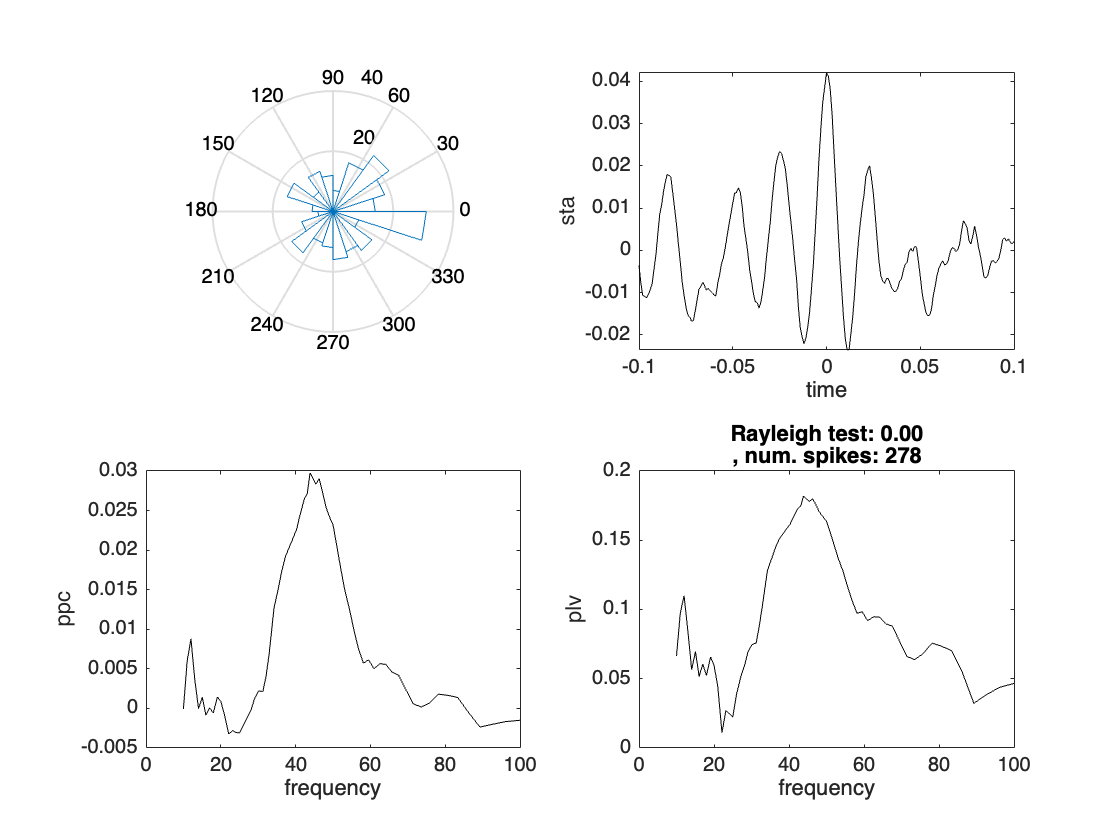

the input is spike data with 100 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB


the input is spike data with 100 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB


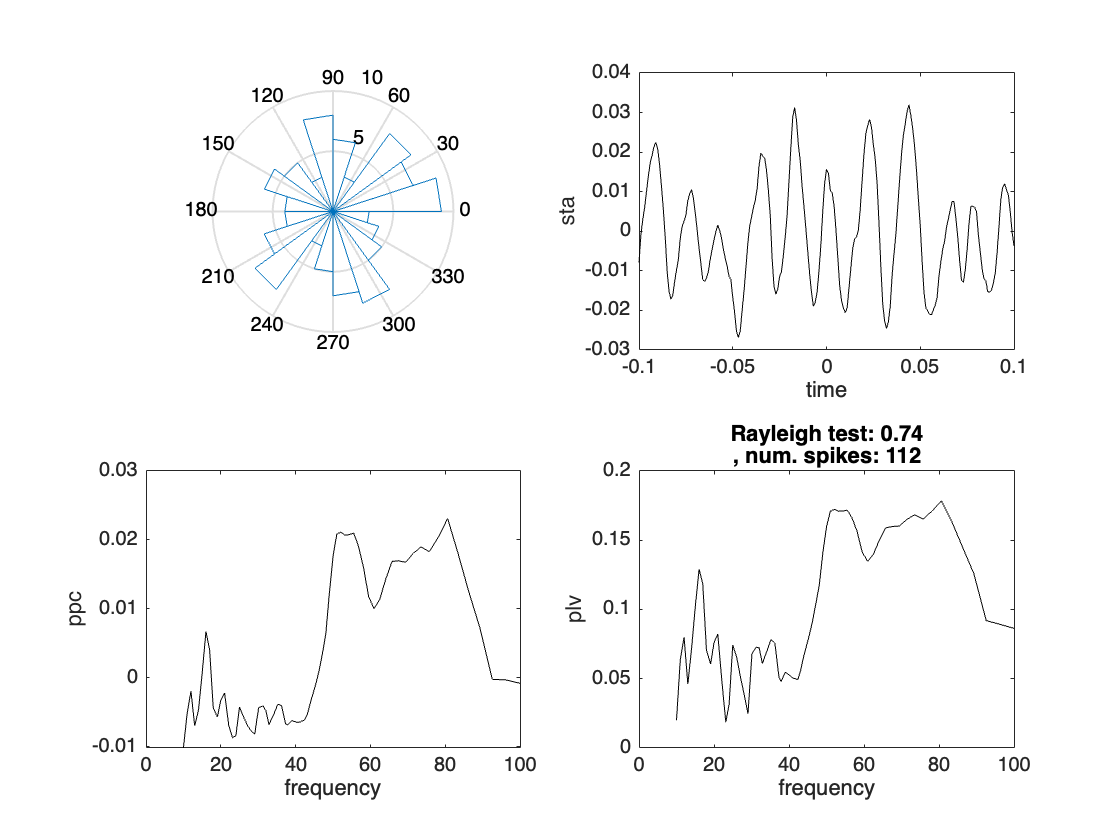

the input is spike data with 100 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB


the input is spike data with 100 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB


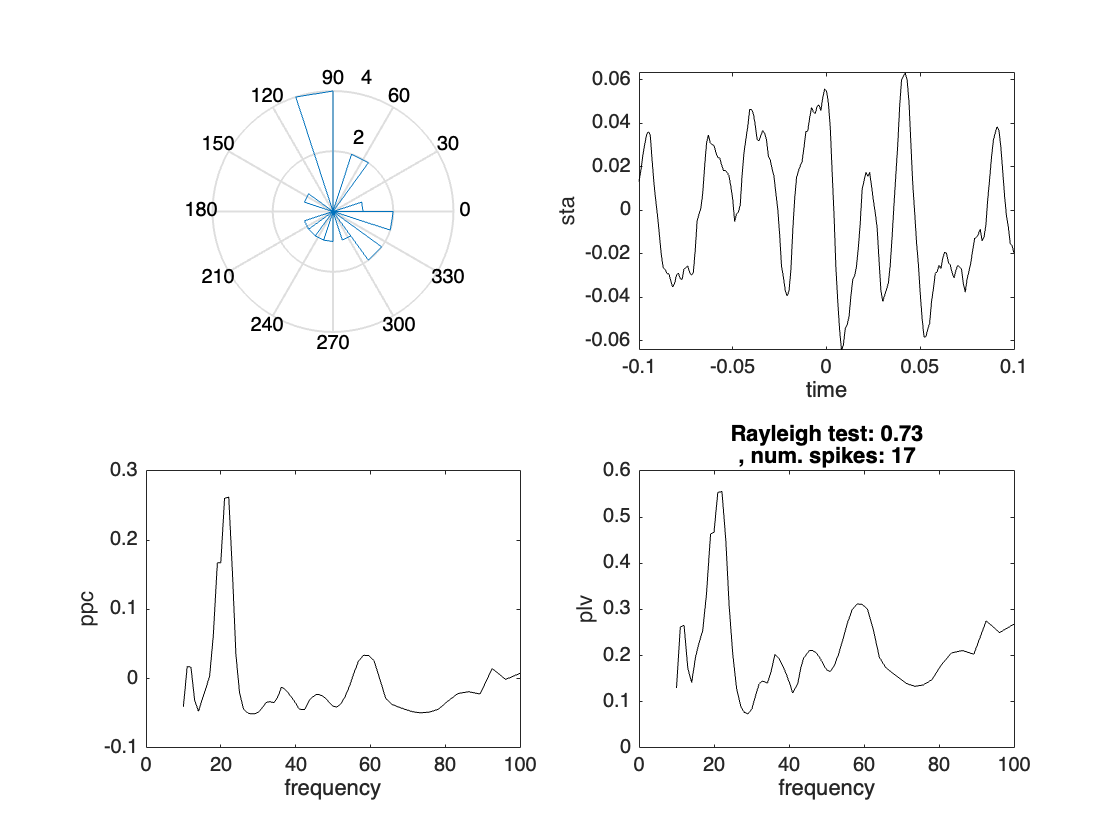

the input is spike data with 100 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB


the input is spike data with 100 channels


Please wait...

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB


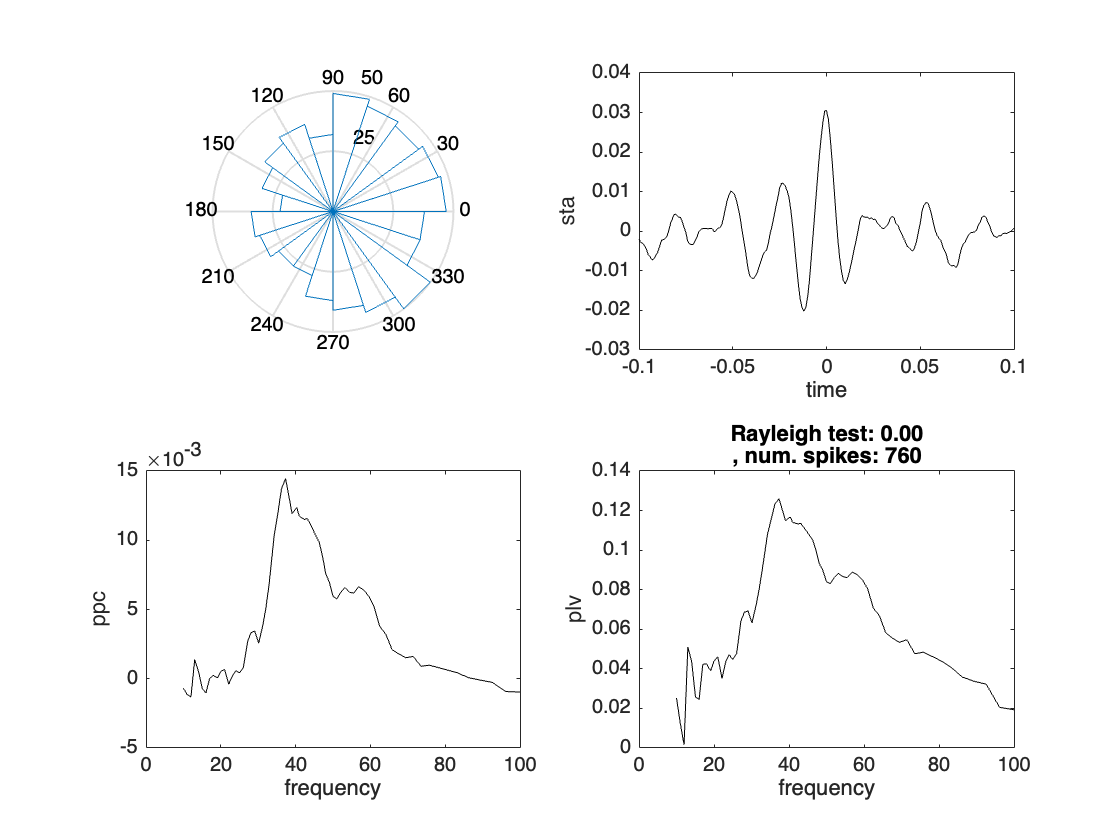


for iNeuron = 1:10
    if length(sts.time{iNeuron})<3, continue,end

    f_ind = nearest(sts.freq, 40); 
    neuron_ind = iNeuron; 
    
    % compute the rayleigh test
    cfg = []; 
    cfg.spikechannel = neuron_ind; 
    cfg.method = 'ral';      
    stat_ral = ft_spiketriggeredspectrum_stat(cfg, sts); % this function takes only one input at a time
    
    % for illustration also show the plv
    cfg = []; 
    cfg.spikechannel = neuron_ind; 
    cfg.method = 'plv';      
    stat_plv = ft_spiketriggeredspectrum_stat(cfg, sts); % this function takes only one input at a time
           
    %
    figure, 
    subplot(2,2,1)
    % visualize the angles for this neuron
    angles = angle(sts.fourierspctrm{iNeuron}(:,:,f_ind));        
    rose(angles,20)        
    
    % visualize the sta
    subplot(2,2,2)
    plot(sta.time, sta_all(iNeuron,:),'k')
    xlabel('time')
    ylabel('sta')

    % visualize the ppc for this neuron
    subplot(2,2,3)
    plot(stat_ppc.freq, ppc_all(iNeuron,:),'k')
    xlabel('frequency')
    ylabel('ppc')
    
    subplot(2,2,4)
    plot(stat_plv.freq, stat_plv.plv,'k')
    xlabel('frequency')
    ylabel('plv')

    title(sprintf("Rayleigh test: %2.2f\n, num. spikes: %d", stat_ral.ral(f_ind),n_spikes(iNeuron,f_ind)))
end

## PART 6: COMPUTE GROUP STATISTICS FOR ALL THE NEURONS

## weighted average 

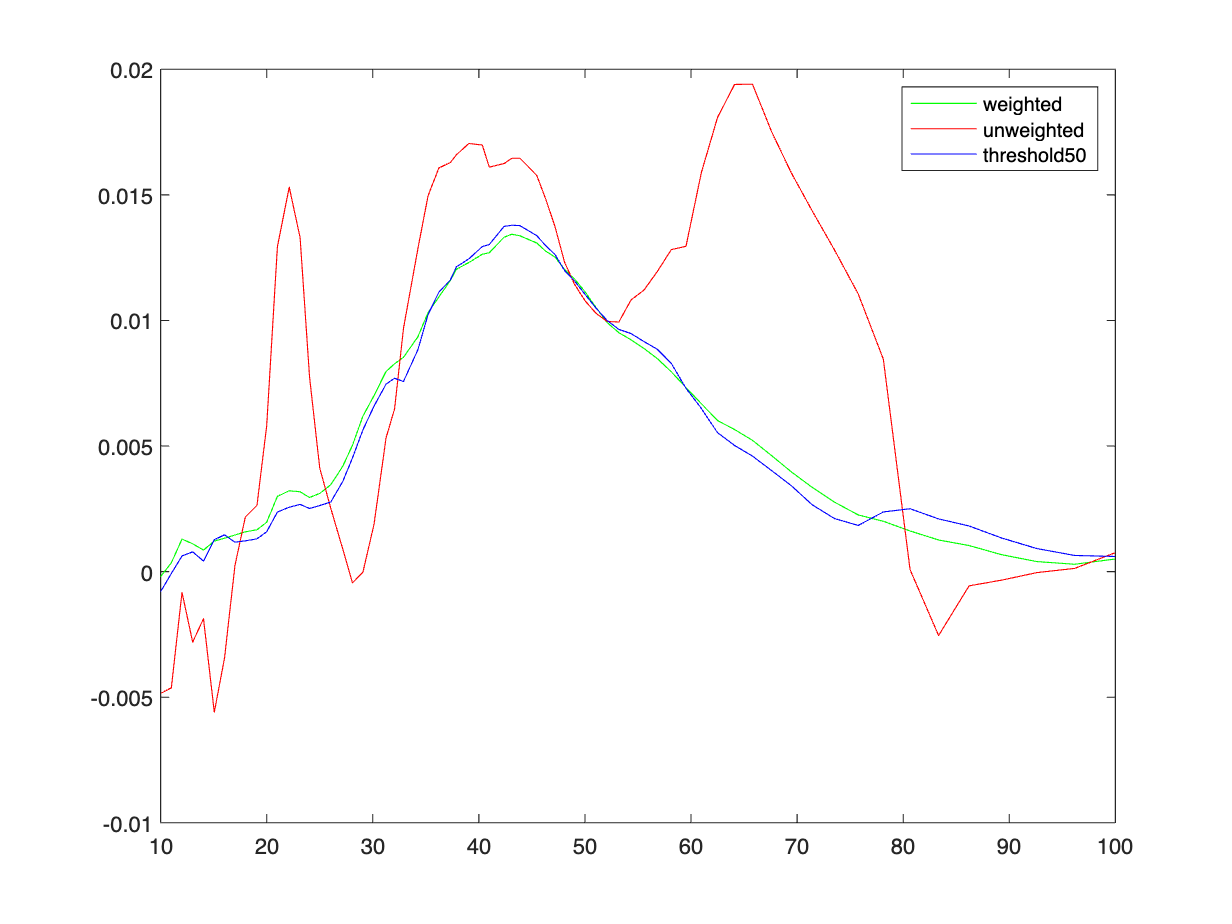

[w_ppc,uw_ppc,thresh_ppc] = compute_avg_ppc(n_spikes,ppc_all);

% plot the results 
figure, 
h(1)=plot(stat_ppc.freq, w_ppc,'g'); 
hold on, 
h(2)=plot(stat_ppc.freq, uw_ppc,'r'); 
hold on, 
h(3)=plot(stat_ppc.freq, thresh_ppc,'b');
legend(h,'weighted', 'unweighted', 'threshold50')

## PART 7: COMPUTE THE SPECTRUM IN A DIFFERENT WAY, TAKING THE FOURIER AROUND EACH SPIKE

cfg = []; 
cfg.timwin= [-0.1 0.1]; 
cfg.foilim = [10 100]; 
cfg.taper = 'hann'; 
cfg.spikechannel = 1:length(spike.trial); 
sts_fft = ft_spiketriggeredspectrum_fft(cfg, lfp, spike); 

the input is raw data with 1 channels and 100 trials
the input is spike data with 100 channels
Please wait...
spectrally decomposing data for trial 100 of 100, 0 spikes for unit 100

the call to "ft_spiketriggeredspectrum_fft" took 8 seconds and required the additional allocation of an estimated 9 MB



% 
nNeurons = length(spike.label); 
ppc_all = NaN(nNeurons, length(sts_fft.freq)); 
n_spikes = NaN(nNeurons, length(sts_fft.freq)); 
for iNeuron = 1:nNeurons

    if length(sts.time{iNeuron})<3, continue,end 
    
    % the code to compute for a single neuron
    cfg = []; 
    cfg.spikechannel = iNeuron; 
    cfg.method = 'ppc1'; 
    stat_ppc = ft_spiketriggeredspectrum_stat(cfg, sts_fft); % this function takes only one input at a time
    
    % collect the data in some array for all neurons
    ppc_all(iNeuron,:) = stat_ppc.ppc1; % collect the ppc values across units
    n_spikes(iNeuron,:) = stat_ppc.nspikes; % collect the number of spikes for each neuron
end

the input is spike data with 100 channels


Please wait...
Processing trial 21 from 21

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 1 MB
the input is spike data with 100 channels


Please wait...
Processing trial 97 from 97

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 100 from 100

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 90 from 90

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 5 from 5

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 96 from 96

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 91 from 91

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 65 from 65

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 16 from 16

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 100 from 100

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 80 from 80

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 36 from 36

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 100 from 100

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 75 from 75

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 98 from 98

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 1 MB
the input is spike data with 100 channels


Please wait...
Processing trial 99 from 99

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 1 MB
the input is spike data with 100 channels


Please wait...
Processing trial 99 from 99

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 1 MB
the input is spike data with 100 channels


Please wait...
Processing trial 92 from 92

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 1 MB
the input is spike data with 100 channels


Please wait...
Processing trial 87 from 87

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 1 MB
the input is spike data with 100 channels


Please wait...
Processing trial 46 from 46

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 1 MB
the input is spike data with 100 channels


Please wait...
Processing trial 41 from 41

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 1 MB
the input is spike data with 100 channels


Please wait...
Processing trial 74 from 74

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 1 MB
the input is spike data with 100 channels


Please wait...
Processing trial 94 from 94

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 1 MB
the input is spike data with 100 channels


Please wait...
Processing trial 15 from 15

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 1 MB
the input is spike data with 100 channels


Please wait...
Processing trial 65 from 65

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 1 MB
the input is spike data with 100 channels


Please wait...
Processing trial 99 from 99

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 1 MB
the input is spike data with 100 channels


Please wait...
Processing trial 98 from 98

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 1 MB
the input is spike data with 100 channels


Please wait...
Processing trial 88 from 88

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 1 MB
the input is spike data with 100 channels


Please wait...
Processing trial 47 from 47

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 1 MB
the input is spike data with 100 channels


Please wait...
Processing trial 78 from 78

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 1 MB
the input is spike data with 100 channels


Please wait...
Processing trial 54 from 54

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 100 from 100

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 53 from 53

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 75 from 75

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 15 from 15

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 7 from 7

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 42 from 42

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 46 from 46

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 2 MB
the input is spike data with 100 channels


Please wait...
Processing trial 71 from 71

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 2 MB
the input is spike data with 100 channels


Please wait...
Processing trial 73 from 73

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 2 MB
the input is spike data with 100 channels


Please wait...
Processing trial 68 from 68

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 2 MB
the input is spike data with 100 channels


Please wait...
Processing trial 20 from 20

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 2 MB
the input is spike data with 100 channels


Please wait...
Processing trial 97 from 97

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 2 MB
the input is spike data with 100 channels


Please wait...
Processing trial 93 from 93

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 2 MB
the input is spike data with 100 channels


Please wait...
Processing trial 99 from 99

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 2 MB
the input is spike data with 100 channels


Please wait...
Processing trial 64 from 64

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 2 MB
the input is spike data with 100 channels


Please wait...
Processing trial 99 from 99

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 2 MB
the input is spike data with 100 channels


Please wait...
Processing trial 83 from 83

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 2 MB
the input is spike data with 100 channels


Please wait...
Processing trial 91 from 91

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 2 MB
the input is spike data with 100 channels


Please wait...
Processing trial 98 from 98

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 2 MB
the input is spike data with 100 channels


Please wait...
Processing trial 100 from 100

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 2 MB
the input is spike data with 100 channels


Please wait...
Processing trial 97 from 97

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 2 MB
the input is spike data with 100 channels


Please wait...
Processing trial 90 from 90

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 2 MB
the input is spike data with 100 channels


Please wait...
Processing trial 50 from 50

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 2 MB
the input is spike data with 100 channels


Please wait...
Processing trial 68 from 68

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 2 MB
the input is spike data with 100 channels


Please wait...
Processing trial 87 from 87

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 2 MB
the input is spike data with 100 channels


Please wait...
Processing trial 44 from 44

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 2 MB
the input is spike data with 100 channels


Please wait...
Processing trial 100 from 100

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 2 MB
the input is spike data with 100 channels


Please wait...
Processing trial 100 from 100

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 2 MB
the input is spike data with 100 channels


Please wait...
Processing trial 100 from 100

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 2 MB
the input is spike data with 100 channels


Please wait...
Processing trial 79 from 79

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 2 MB
the input is spike data with 100 channels


Please wait...
Processing trial 100 from 100

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 2 MB
the input is spike data with 100 channels


Please wait...
Processing trial 55 from 55

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 2 MB
the input is spike data with 100 channels


Please wait...
Processing trial 58 from 58

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 2 MB
the input is spike data with 100 channels


Please wait...
Processing trial 93 from 93

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 3 MB
the input is spike data with 100 channels


Please wait...
Processing trial 39 from 39

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 3 MB
the input is spike data with 100 channels


Please wait...
Processing trial 100 from 100

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 3 MB
the input is spike data with 100 channels


Please wait...
Processing trial 14 from 14

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 3 MB
the input is spike data with 100 channels


Please wait...
Processing trial 63 from 63

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 93 from 93

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 93 from 93

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 91 from 91

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 95 from 95

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 76 from 76

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 45 from 45

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 60 from 60

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 54 from 54

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 94 from 94

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 89 from 89

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 3 from 3

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 100 from 100

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 79 from 79

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 59 from 59

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 75 from 75

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 94 from 94

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 99 from 99

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 57 from 57

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 72 from 72

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 95 from 95

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 91 from 91

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 63 from 63

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 30 from 30

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 99 from 99

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 41 from 41

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 0 MB
the input is spike data with 100 channels


Please wait...
Processing trial 91 from 91

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 2 MB
the input is spike data with 100 channels


Please wait...
Processing trial 99 from 99

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 2 MB
the input is spike data with 100 channels


Please wait...
Processing trial 97 from 97

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 2 MB
the input is spike data with 100 channels


Please wait...
Processing trial 65 from 65

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 2 MB
the input is spike data with 100 channels


Please wait...
Processing trial 100 from 100

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 2 MB
the input is spike data with 100 channels


Please wait...
Processing trial 40 from 40

the call to "ft_spiketriggeredspectrum_stat" took 0 seconds and required the additional allocation of an estimated 2 MB


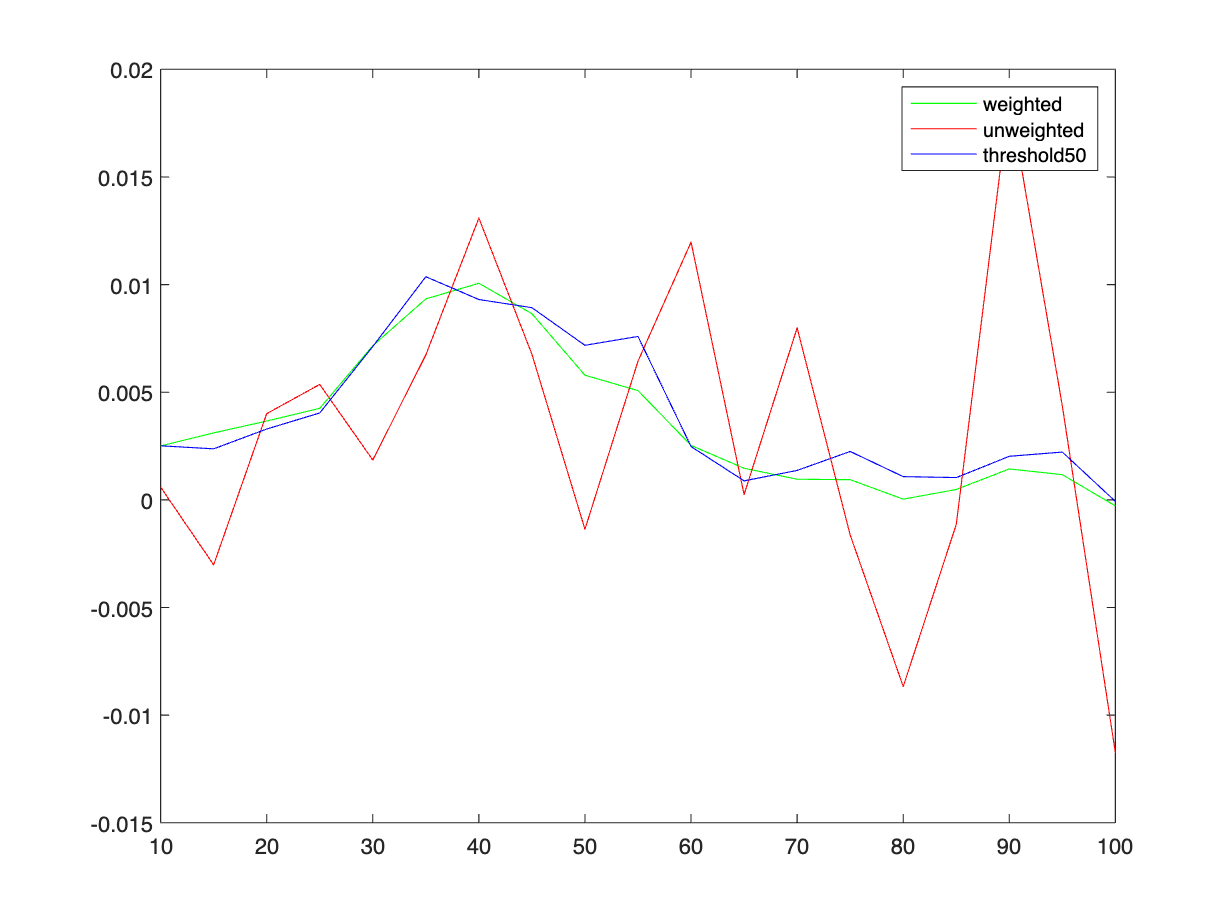


%
[w_ppc,uw_ppc,thresh_ppc] = compute_avg_ppc(n_spikes,ppc_all);

% plot the results 
figure, 
h(1)=plot(stat_ppc.freq, w_ppc,'g'); 
hold on, 
h(2)=plot(stat_ppc.freq, uw_ppc,'r'); 
hold on, 
h(3)=plot(stat_ppc.freq, thresh_ppc,'b');
legend(h,'weighted', 'unweighted', 'threshold50')

## PART 8: COMPUTE THE SPIKE FIELD COHERENCE

cfg = []; 
cfg.method = 'mtmfft'; 
cfg.taper = 'dpss';
cfg.foilim = [1 100];
cfg.tapsmofrq = 8;
cfg.output = 'fourier';
ft = ft_freqanalysis(cfg, data_all);

cfg = []; 
cfg.method = 'coh';
con = ft_connectivityanalysis(cfg, ft); 

coh_spike_lfp = squeeze(con.cohspctrm(1,:,:));
figure, plot(con.freq, nanmean(coh_spike_lfp,1)); 


## 
$$END$$
